#  Design, Operation, and Control of Remote Microgrid 

This design solution shows how to develop, evaluate, and operate a remote microgrid. In this study you also evaluate microgrid operations, microgrid control, and microgrid controller functions against various standards. This workflow refers to these standards:

- IEEE Std 2030.9-2019: IEEE Recommended Practice for the Planning and Design of the Microgrid

- IEC TS 62898-1:2017: Microgrids – Part 1: Guidelines for microgrid projects planning and specification

-  IEEE Std 2030.7-2017: IEEE Standard for the Specification of Microgrid Controllers

- IEEE Std 2030.8-2018: IEEE Standard for the Testing of Microgrid Controllers

- IEEE STD 2030.2.1-2019: IEEE Guide for Design, Operation, and Maintenance of Battery Energy Storage Systems, both Stationary and Mobile, and Applications Integrated with Electric Power Systems

## **Standards **

#### **IEEE Std 2030.9-2019: IEEE Recommended Practice for the Planning and Design of the Microgrid**

Once you identify the planning objective and system configuration, you complete the electrical and automation system designs. Electrical design covers the selection of voltage, point of common coupling (PCC), grid structure, earthing, and the analysis and calculation for equipment selection. The automation system design covers the protection, monitoring, communication, measurements with energy management, and power quality. You generate various schemes for comparison and evaluation before the selection of the preferred microgrid scheme. 

The planning objective in this remote microgrid study includes power reliability, renewable power usage, and reduction in diesel consumption. To supply one low-voltage (LV) load secondary substation and one medium-voltage (MV) load, this workflow implements a system with two feeders with normally open switch at the remote end. Each microgrid asset receives commands from the microgrid controller and sends key measurements to the control room. Feeder breakers and additional breakers at each connecting asset protect the microgrid.

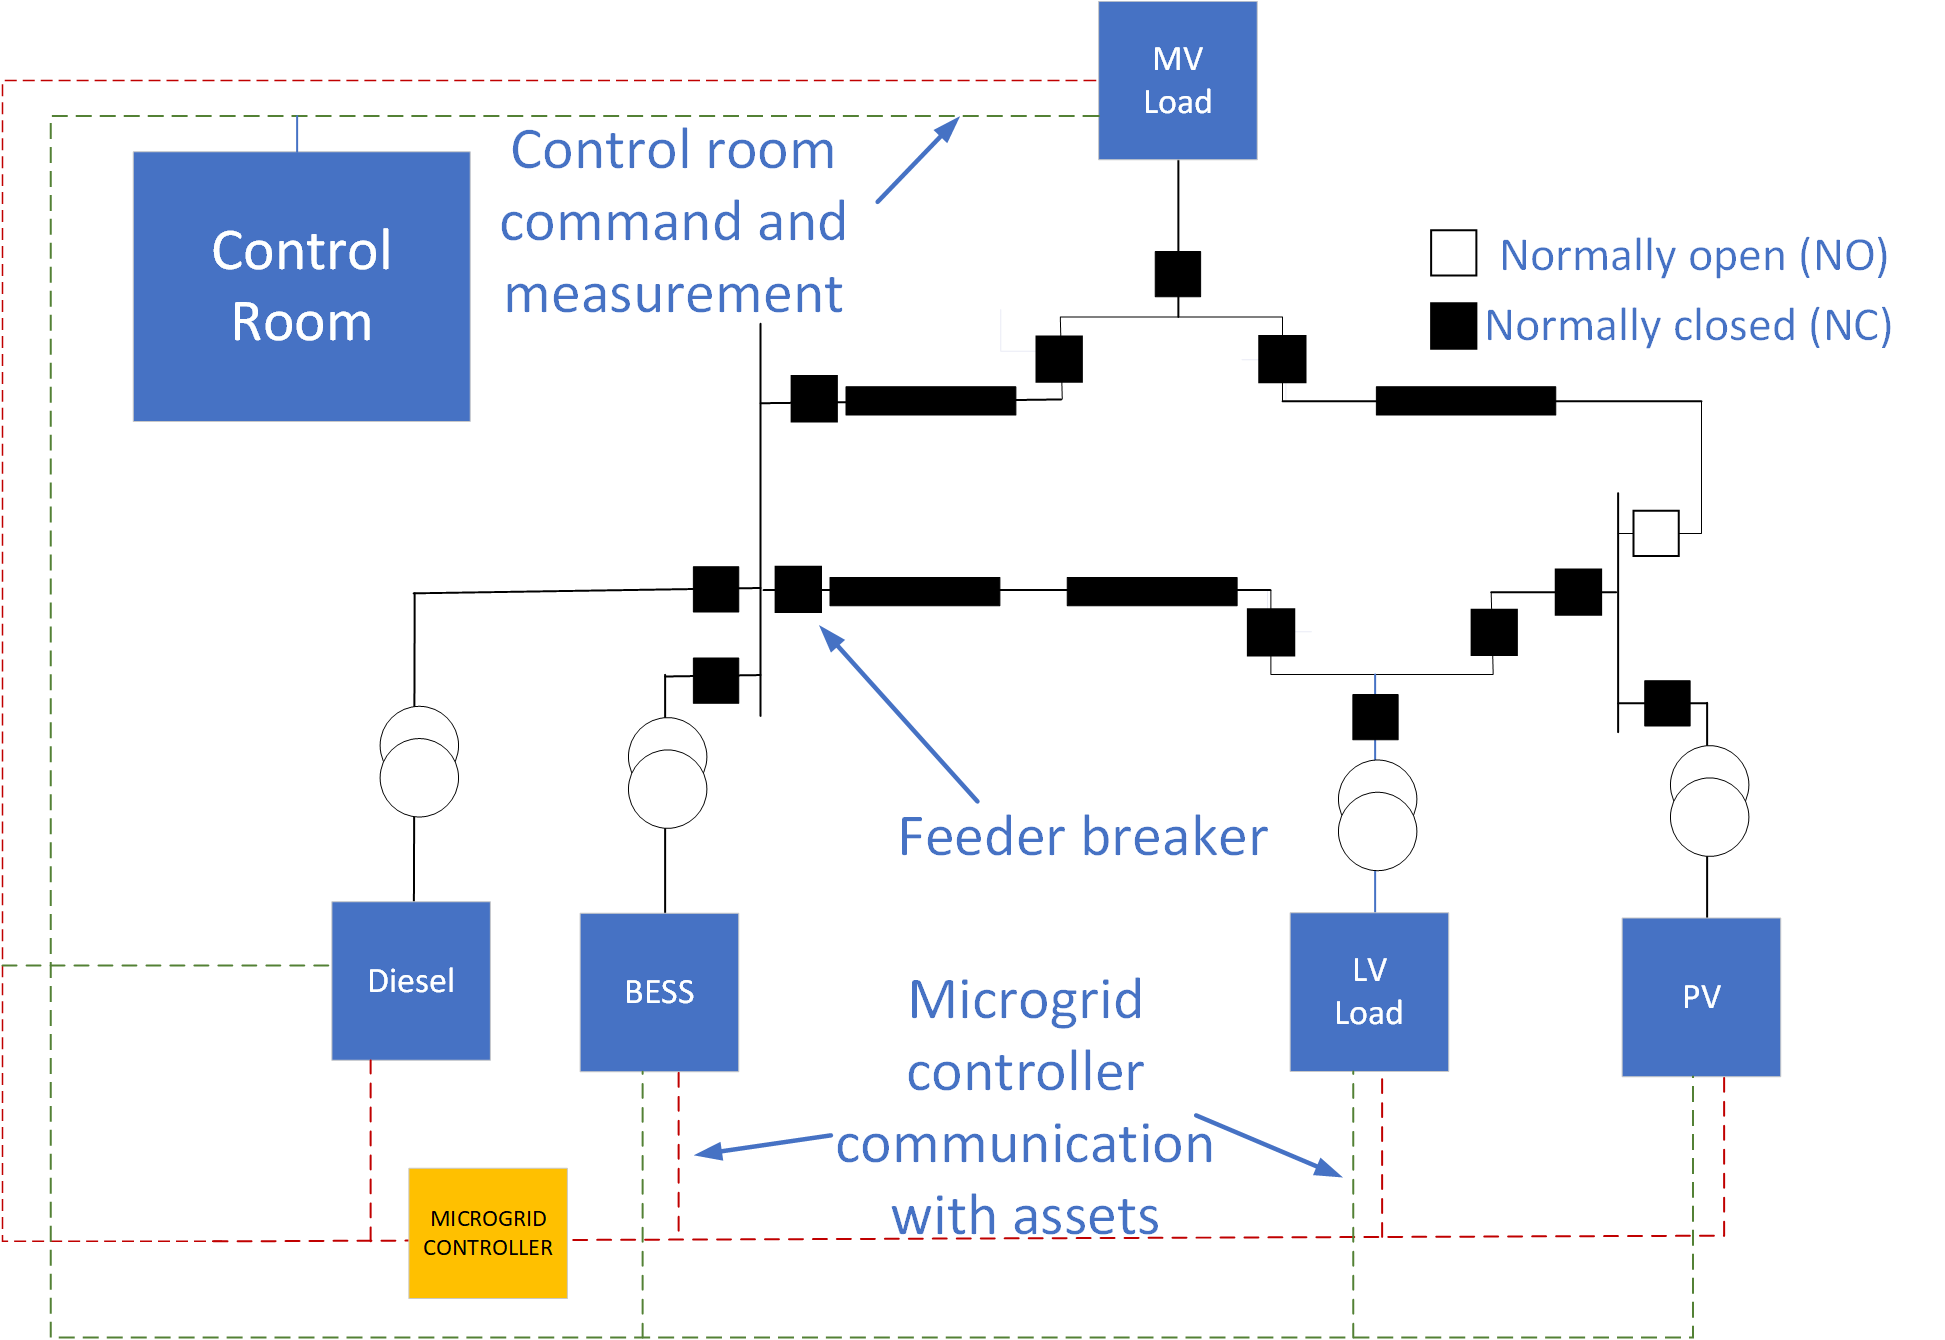

The key indices for economic benefits for the remote microgrid include life cycle cost, net revenue, payback period, and internal rate of return. In this workflow, these indices are improved through reduction in diesel usage, maximum usage of renewable energy, and operation of the BESS. 

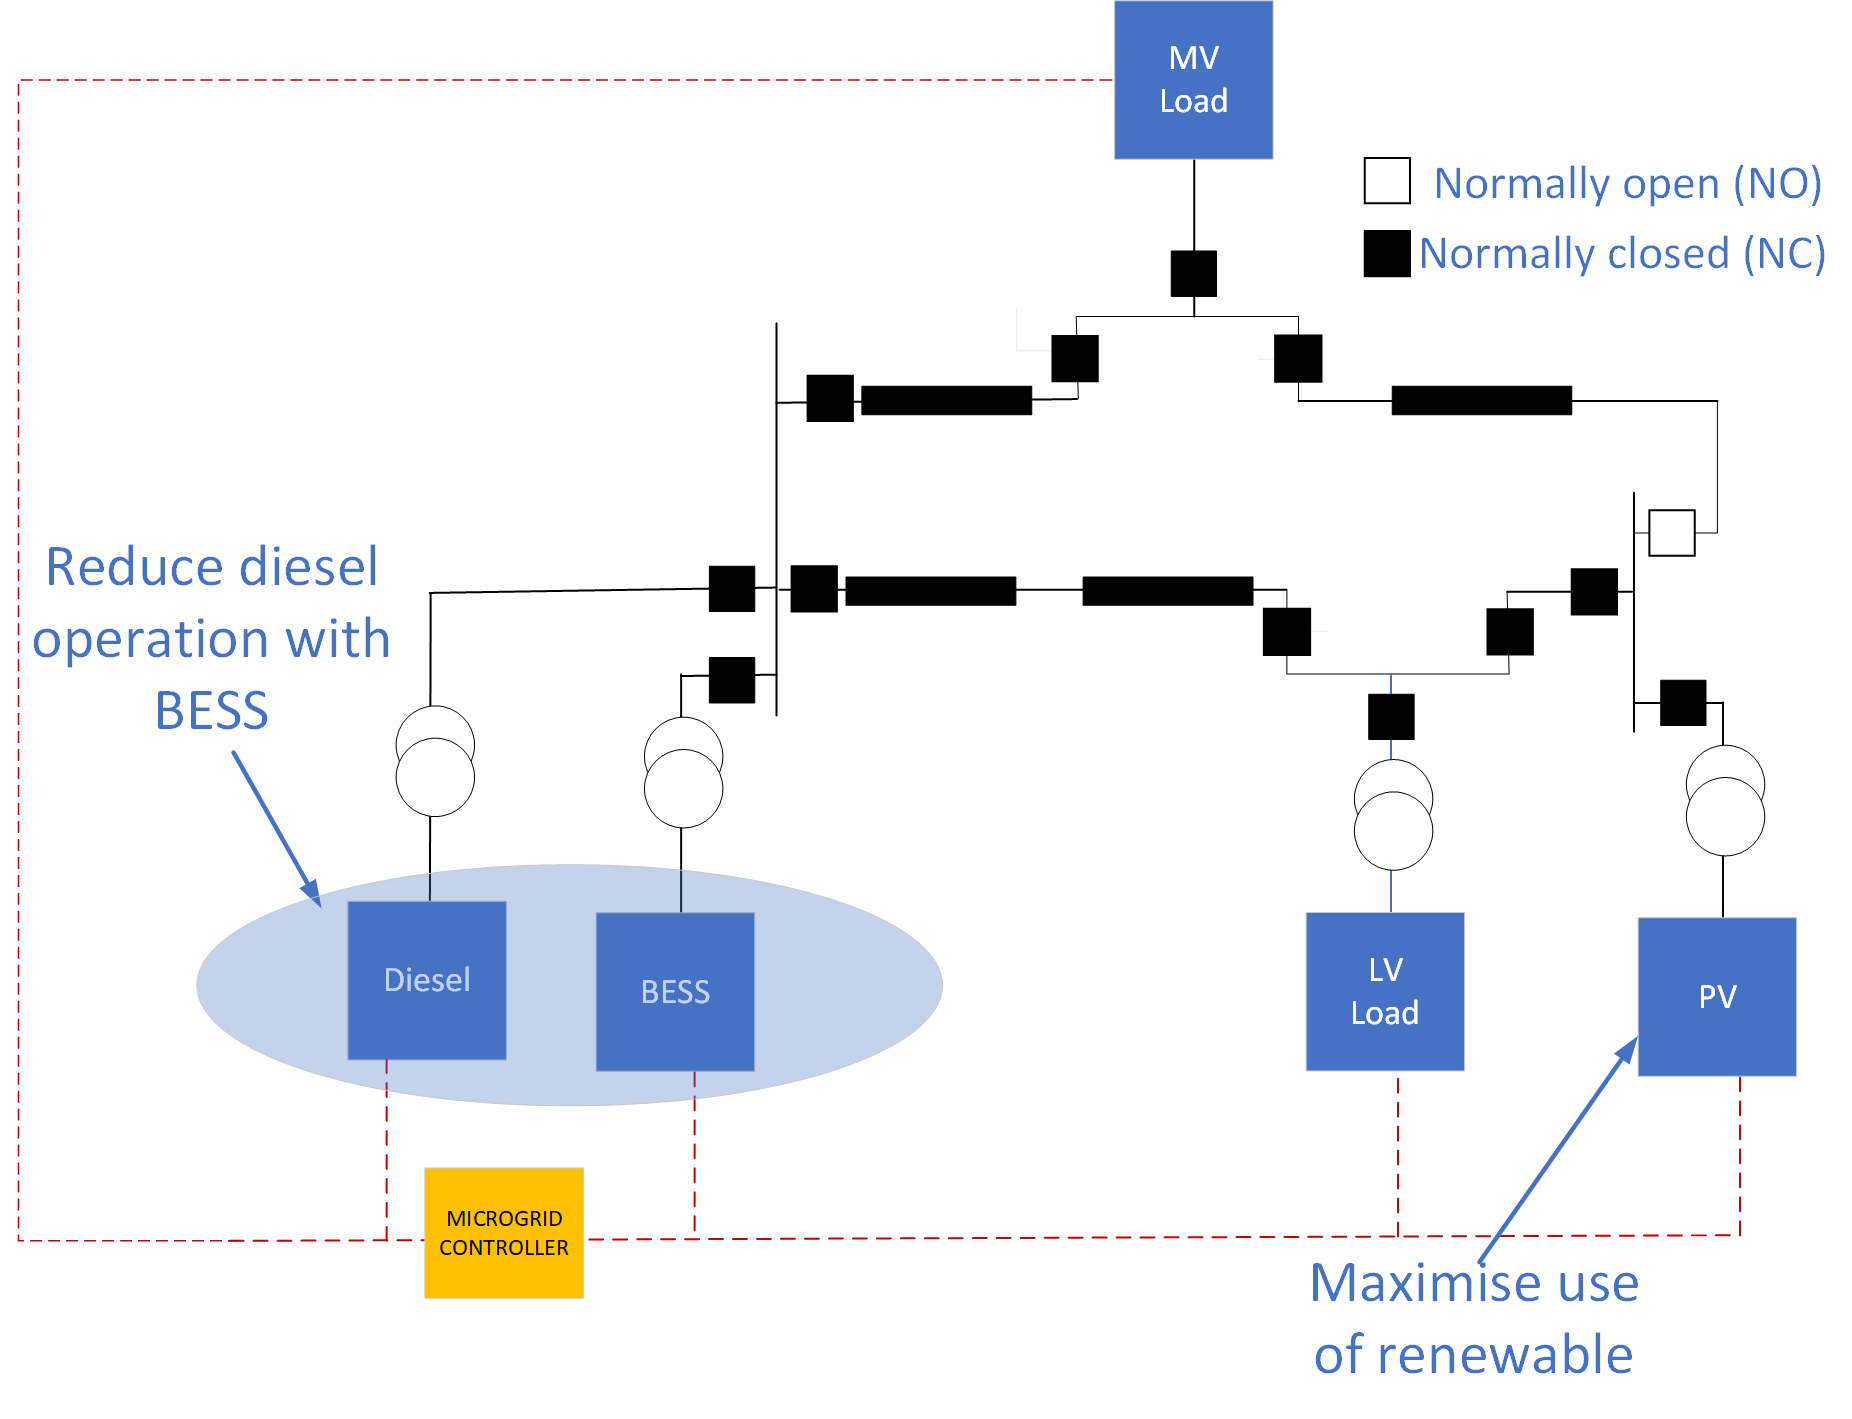

#### **IEC TS 62898-1:2017: Microgrids – Part 1: Guidelines for microgrid projects planning and specification**

 The basic design steps for the microgrid include:

- The preliminary study with objective, generation, and load forecast. This study considers the maximum and minimum loads to decide the operation of diesel with the BESS.

- Microgrid and system planning. With two outgoing feeders at MV level, this study connects the remote photovoltaic (PV), MV load, and the LV load through the secondary substation (SS).

- To maintain the technical requirements for the resource, network, control, and protection, this study monitors the steady state and dynamic limits, THD, and settling time in various control functions.

- In the evaluation, the reduction of diesel usage is used as the improvement in economic performance while continuous supply to loads validates the reliability. Other structural and scalability analyses are out of scope for this workflow.

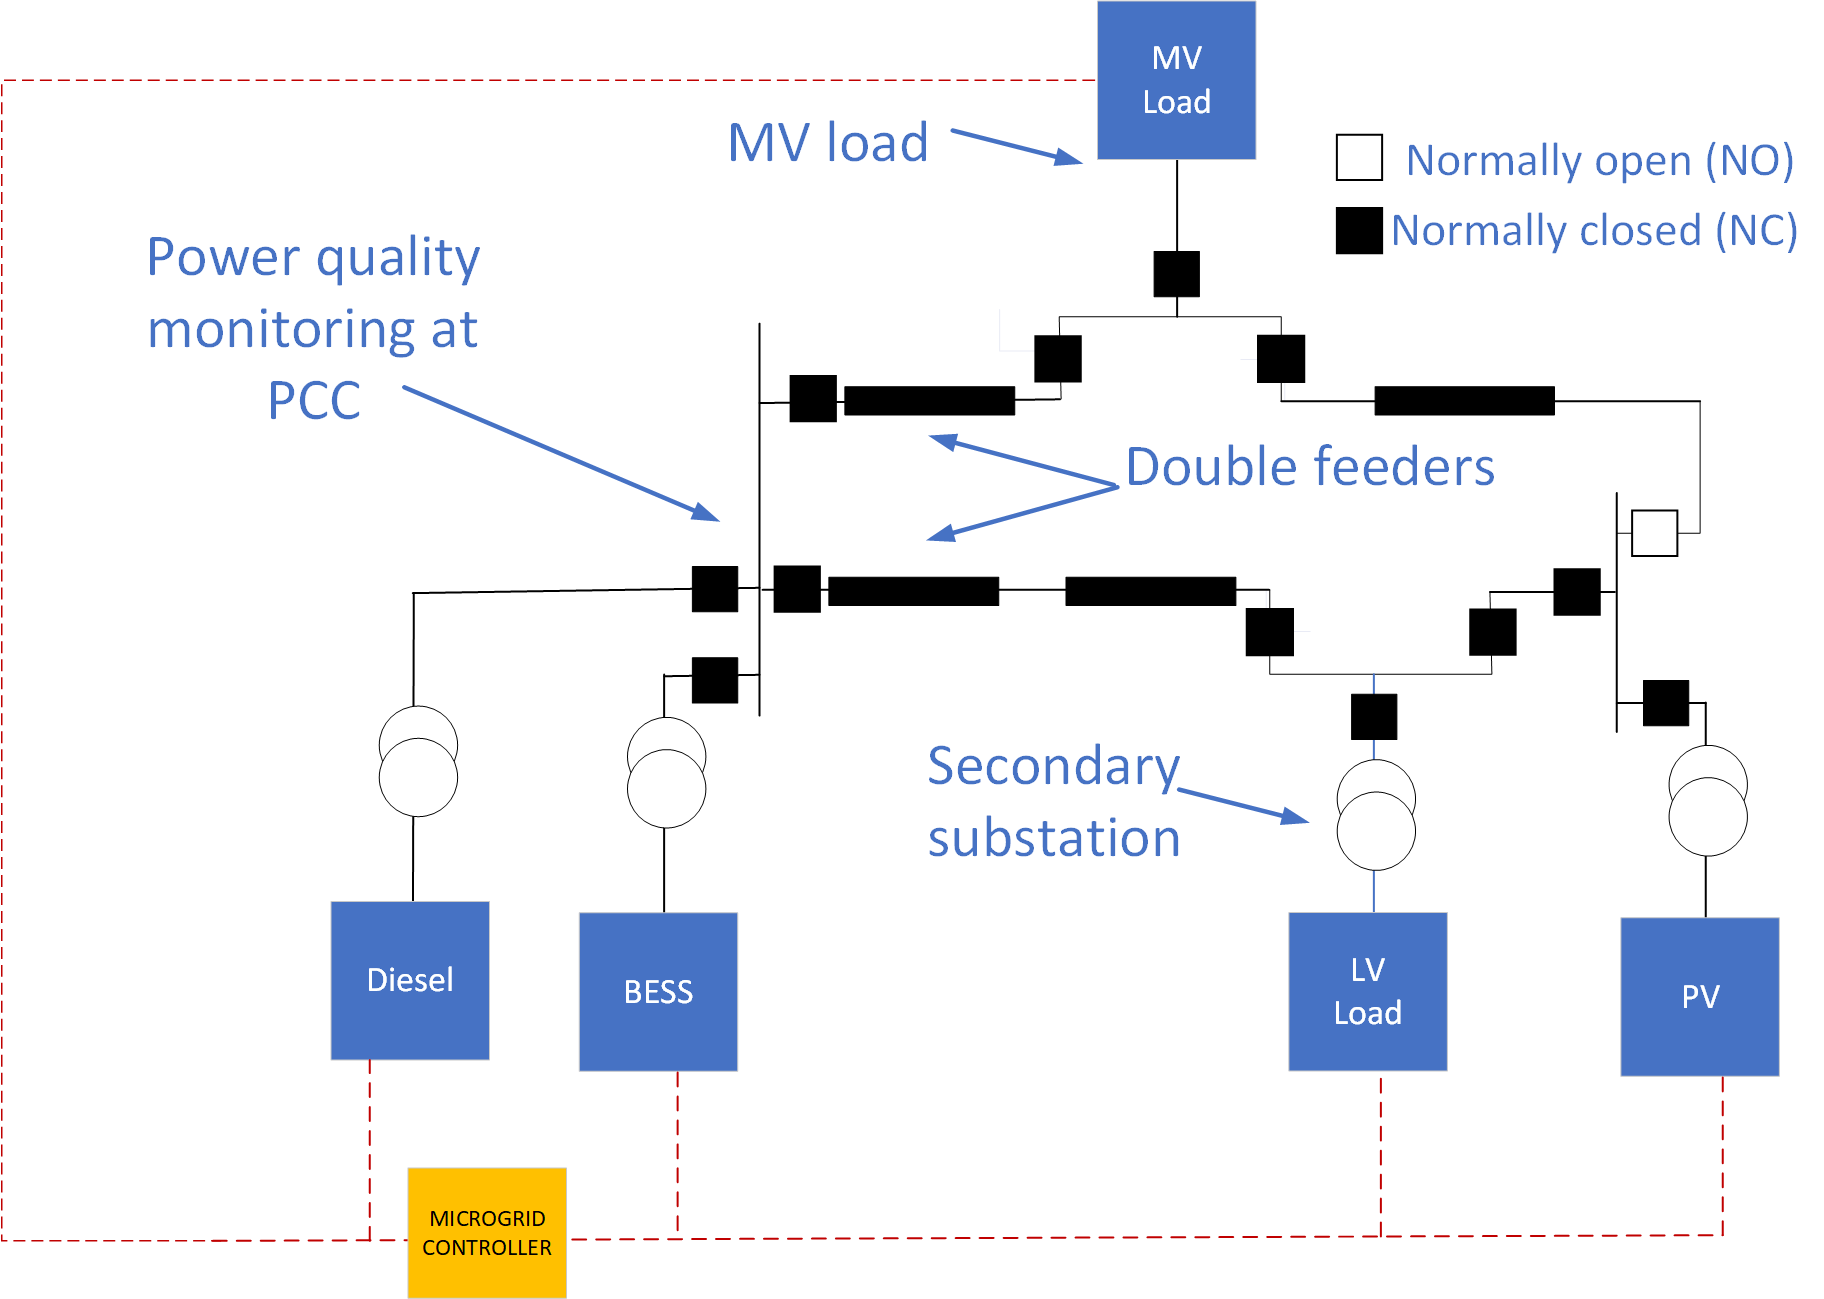

####  **IEEE Std 2030.7-2017: IEEE Standard for the Specification of Microgrid Controllers**

One of the key microgrid functions in a remote microgrid is dispatch. The dispatch core function provides these functionalities: 

- Balancing generation and loads. 

- Dispatching controllable resources. 

- Responding to external orders and events.

The dispatch functions include the dispatch control, breaker, switches operation, and voltage regulation. In this workflow, the operator from the operator room performs the dispatch control and operates the breakers. The diesel and the BESS voltage controlling actions regulate the voltage. You can consider additional capacitor switching or tap changing transformers if necessary. The fundamental performance metrics include dispatch objective, device status, and voltage deviation.

The dispatch function requirements for microgrid controller include the response accuracy and the settling time. In this study, you can test the accuracy and settling of the BESS dispatch by modifying the controller parameters. The setpoint enforcement is ensured at the BESS with measurement of real power, reactive power, voltage, and frequency (P, Q, V, f). The performance is evaluated with steady-state error and transient behaviour. The power quality is monitored with voltage harmonic distortion, current harmonic distortion, and voltage sag. This workflow implements these monitoring under performance evaluation at the control room. You can find more explanations in the modelling sections later.

According to IEEE Std 2030.7-2017, the remote microgrid includes a diesel generator (usually at base load), renewable, distributed or centralized storage, and controllable loads.This workflow implements centralized storage at the substation and demonstrates the coordination of the diesel generator with the BESS.

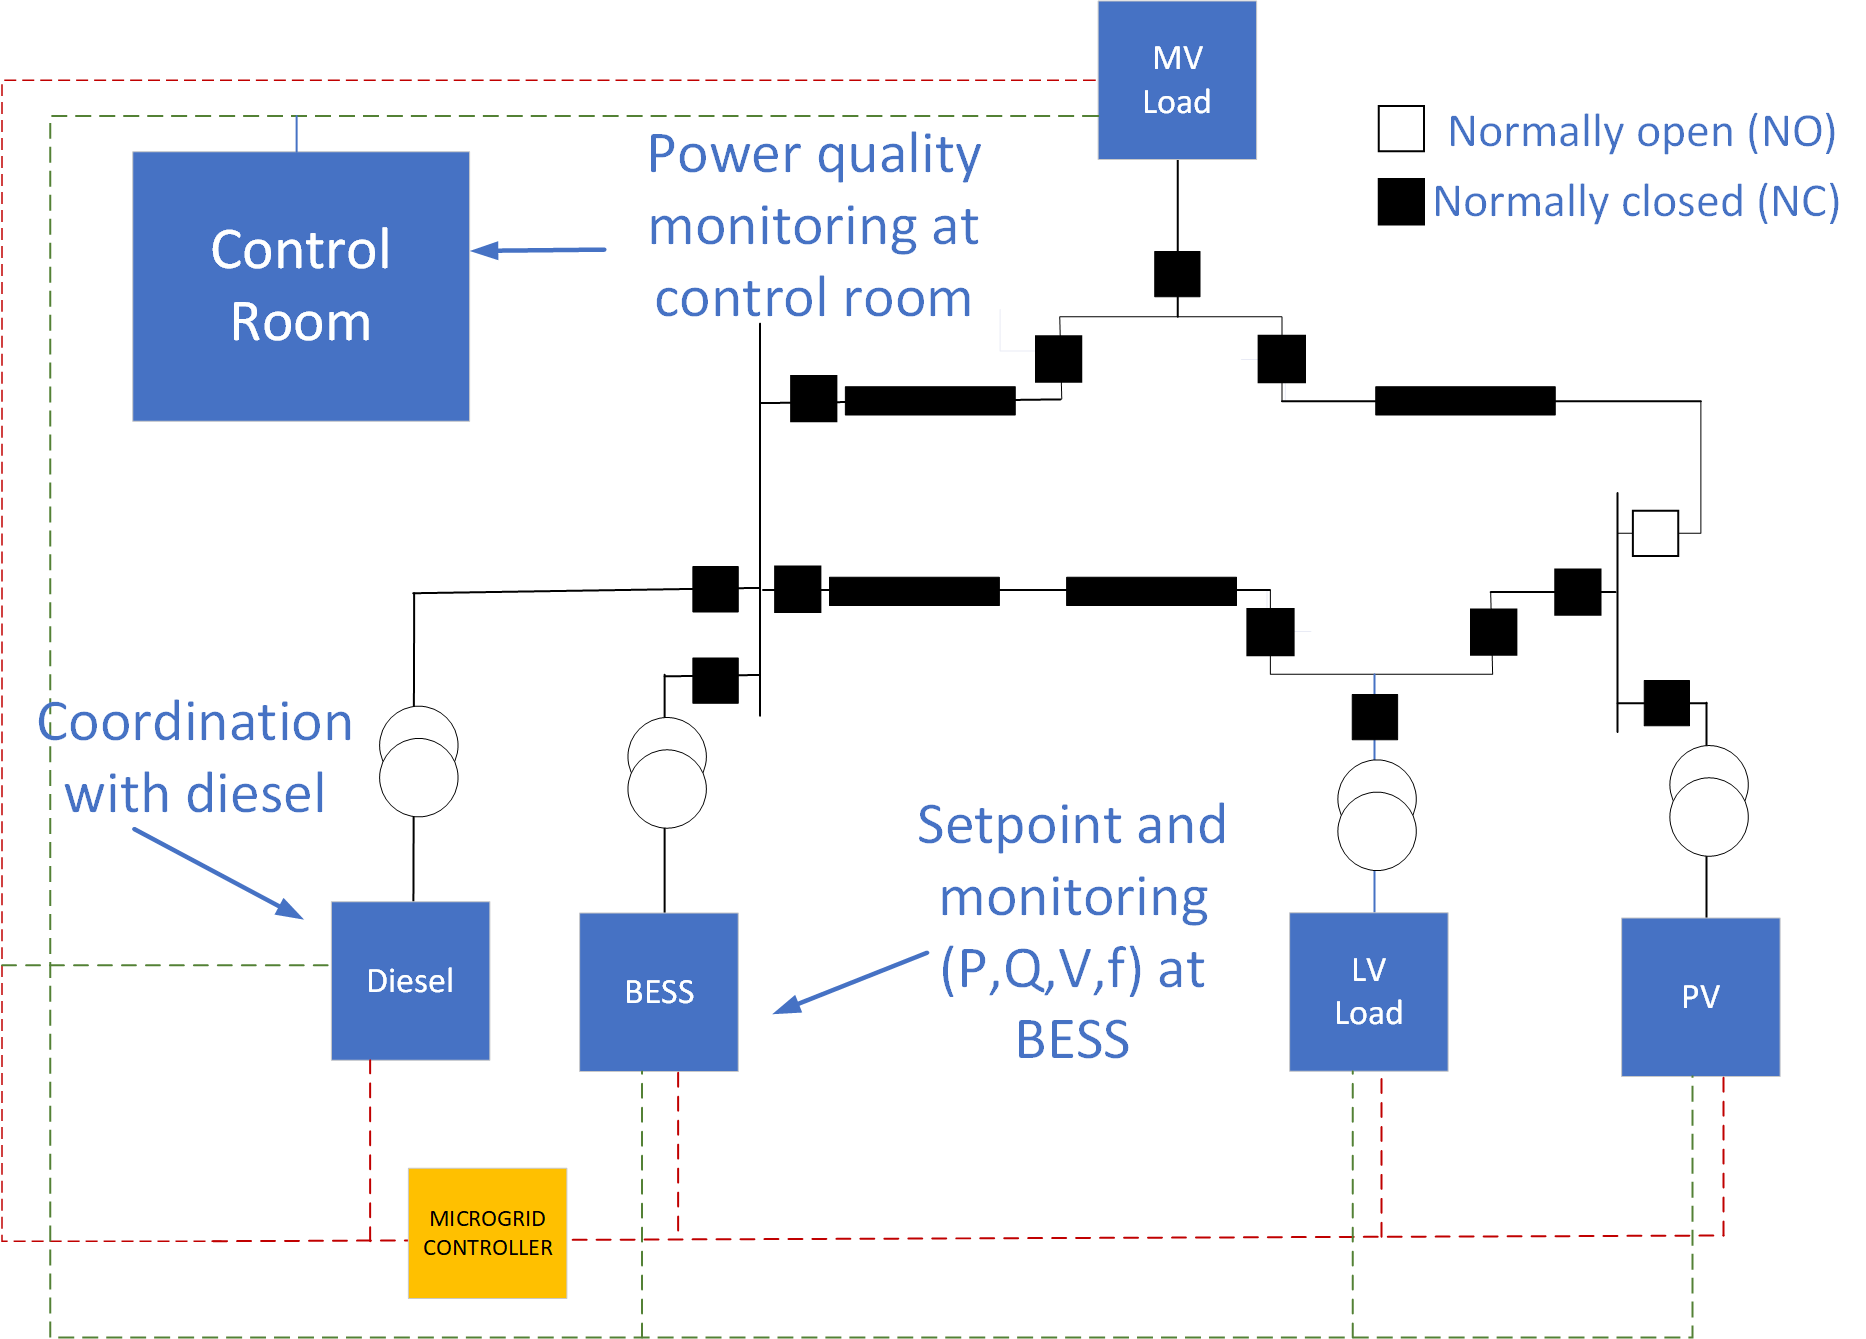

#### **IEEE Std 2030.8-2018: IEEE Standard for the Testing of Microgrid Controllers**

 The structure of the microgrid and the controller follow the **IEEE Std 2030.8-2018 **standard**. **As this is a remote microgrid, there is no main grid connection, and the diesel and BESS are connected at the substation. With the opening and closing of appropriate disconnectors you can supply the LV network from the other MV feeder, where the MV load is connected.

 The data monitoring in this workflow follows the guideline of **IEEE Std 2030.8-2018:**

- Sequence of events for switching device status, command, control output with digital data only with minimum sampling of ¼ of power system cycle.

- Event data for voltage and current of all phases with minimum sampling of ¼ of power system cycle and accuracy of 1% voltage. 

- Continuous data collection for voltage and current of all phases with minimum sampling of 100ms and accuracy of 1% voltage.

In a remote microgrid the voltage and frequency constraints are more relaxed compared to a grid connected microgrid. This might not be true if the remote microgrid is supplying industrial or commercial loads. In this workflow the acceptable limits are $\pm \;0\ldotp 1\;$pu on rated voltage, and $0\ldotp 02$ pu on rated frequency. You can set these limits in the [RemoteMicrogridInputData](matlab:open('./RemoteMicrogridInputData.mlx')).

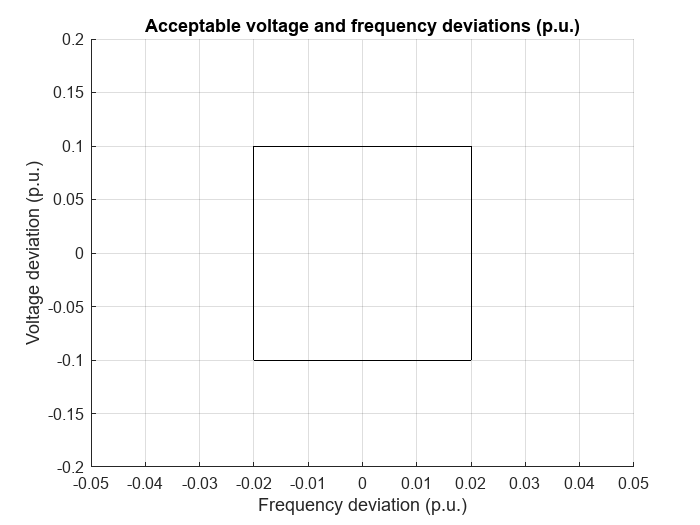

RemoteMicrogridInputData;
rectangle('Position', [-Microgrid.FrequencyLimit,-Microgrid.VoltageLimit,...
    2*Microgrid.FrequencyLimit,2*Microgrid.VoltageLimit])
axis([-0.05,0.05,-0.2,0.2])
grid on
xlabel('Frequency deviation (p.u.)')
ylabel('Voltage deviation (p.u.)')
title('Acceptable voltage and frequency deviations (p.u.)')

#### **IEEE Std 2030.2.1-2019: IEEE Guide for Design, Operation, and Maintenance of Battery Energy Storage **

The basic functionality of the BESS in grid application includes frequency regulation, voltage regulation, and emergency backup.This study only demonstrates the BESS function for load following, grid forming, set point tracking, planned diesel switch off, and resynchronization to diesel. For the hardware design, the study model implements a single AC/DC link and an output filter. By using Simscape(TM) Electrical(TM), you can easily implement other designs with multiple AC/DC stages and parallel links for the conversion stage.

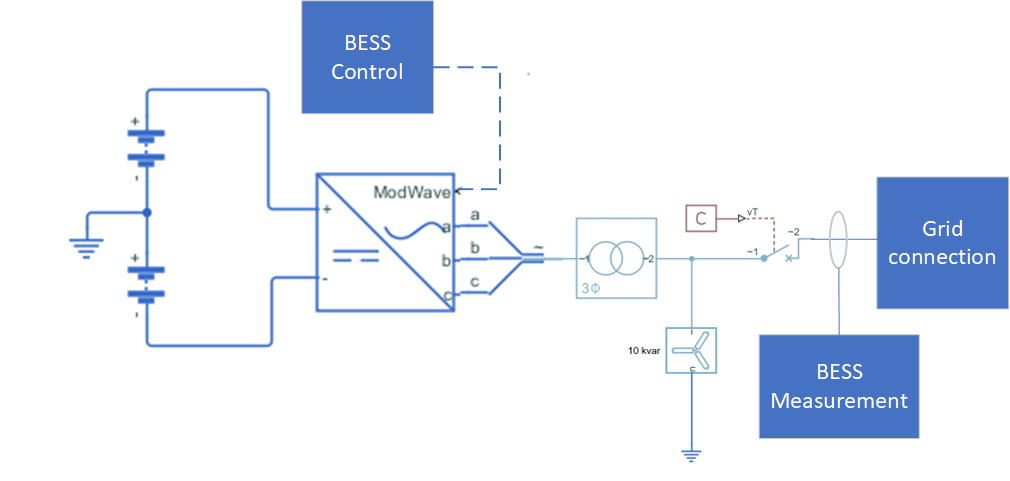

This figure shows various aspects from different standards considered in this workflow.

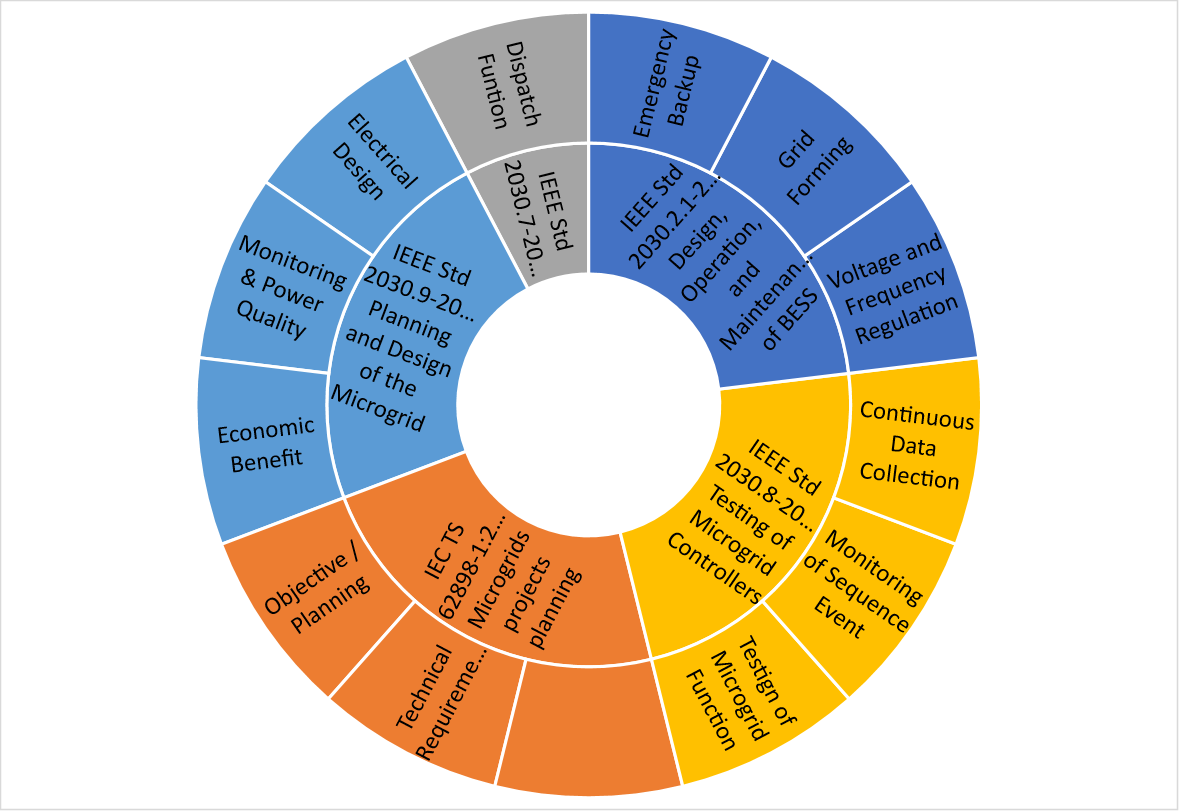

## Remote Microgrid

The microgrid in this model comprises: 

- Power generation sources for diesel generation and photovoltaic generation.

- A battery energy storage system.

- A MV load and a LV load.

- A substation with two outgoing feeders.

- A microgrid controller at the substation.

### Description of Remote Microgrid 

The remote microgrid network comprises these components and connections:

#### Generation and Storage

There are two power generation units and one storage system.

- Diesel generator with associated control – The diesel generator generates active power and controls voltage.

- Photovoltaic generation connected through interfacing converter with associated control – The PV system in this study uses a three-phase convertor that injects power with unity power factor (UPF) without an intermediate DC-DC converter. 

- The storage unit is a BESS system with associated control – The BESS controller receives commands and setpoint from the microgrid controller. The BESS in this model comprises functions to receive setpoint/references and command from operator, control the converter to track the reference quantities, and change control mode.

#### Load

There are two loads:

- An MV load that connects to the medium voltage line

- An LV load that connects secondary substation

#### Substation and Network

A substation connects the diesel generator to the microgrid at the PCC. It hosts the diesel generator and the BESS connected at the PCC. The diesel and BESS connections are implemented with associated transformers and breakers. The microgrid controller is also implemented at the substation.

Two outgoing MV feeders from the substation connect the microgrid assets. The feeders are connected at the remote end with a normally open switch. The MV load and the PV are connected at Feeder 1 while the LV load is connected at Feeder 2 through the secondary substation.

#### System Level Control and Monitoring

The microgrid controller controls the microgrid assets and the microgrid network.

The system level monitoring is performed at the control room where all the measurements are collated. The operator room collates the measurement and sends commands to various assets.

#### Microgrid Controller 

The microgrid controller monitors the microgrid operation and executes different microgrid functions. The microgrid controller commands the BESS with voltage and frequency setpoints. The microgrid controller in this model comprises these functions: 

- Reference frequency generation

- Reference voltage generation

- Breaker control

- Active and reactive power reference generation

- Diesel planned switch off or islanding of diesel

- Start and resynchronization of diesel generator

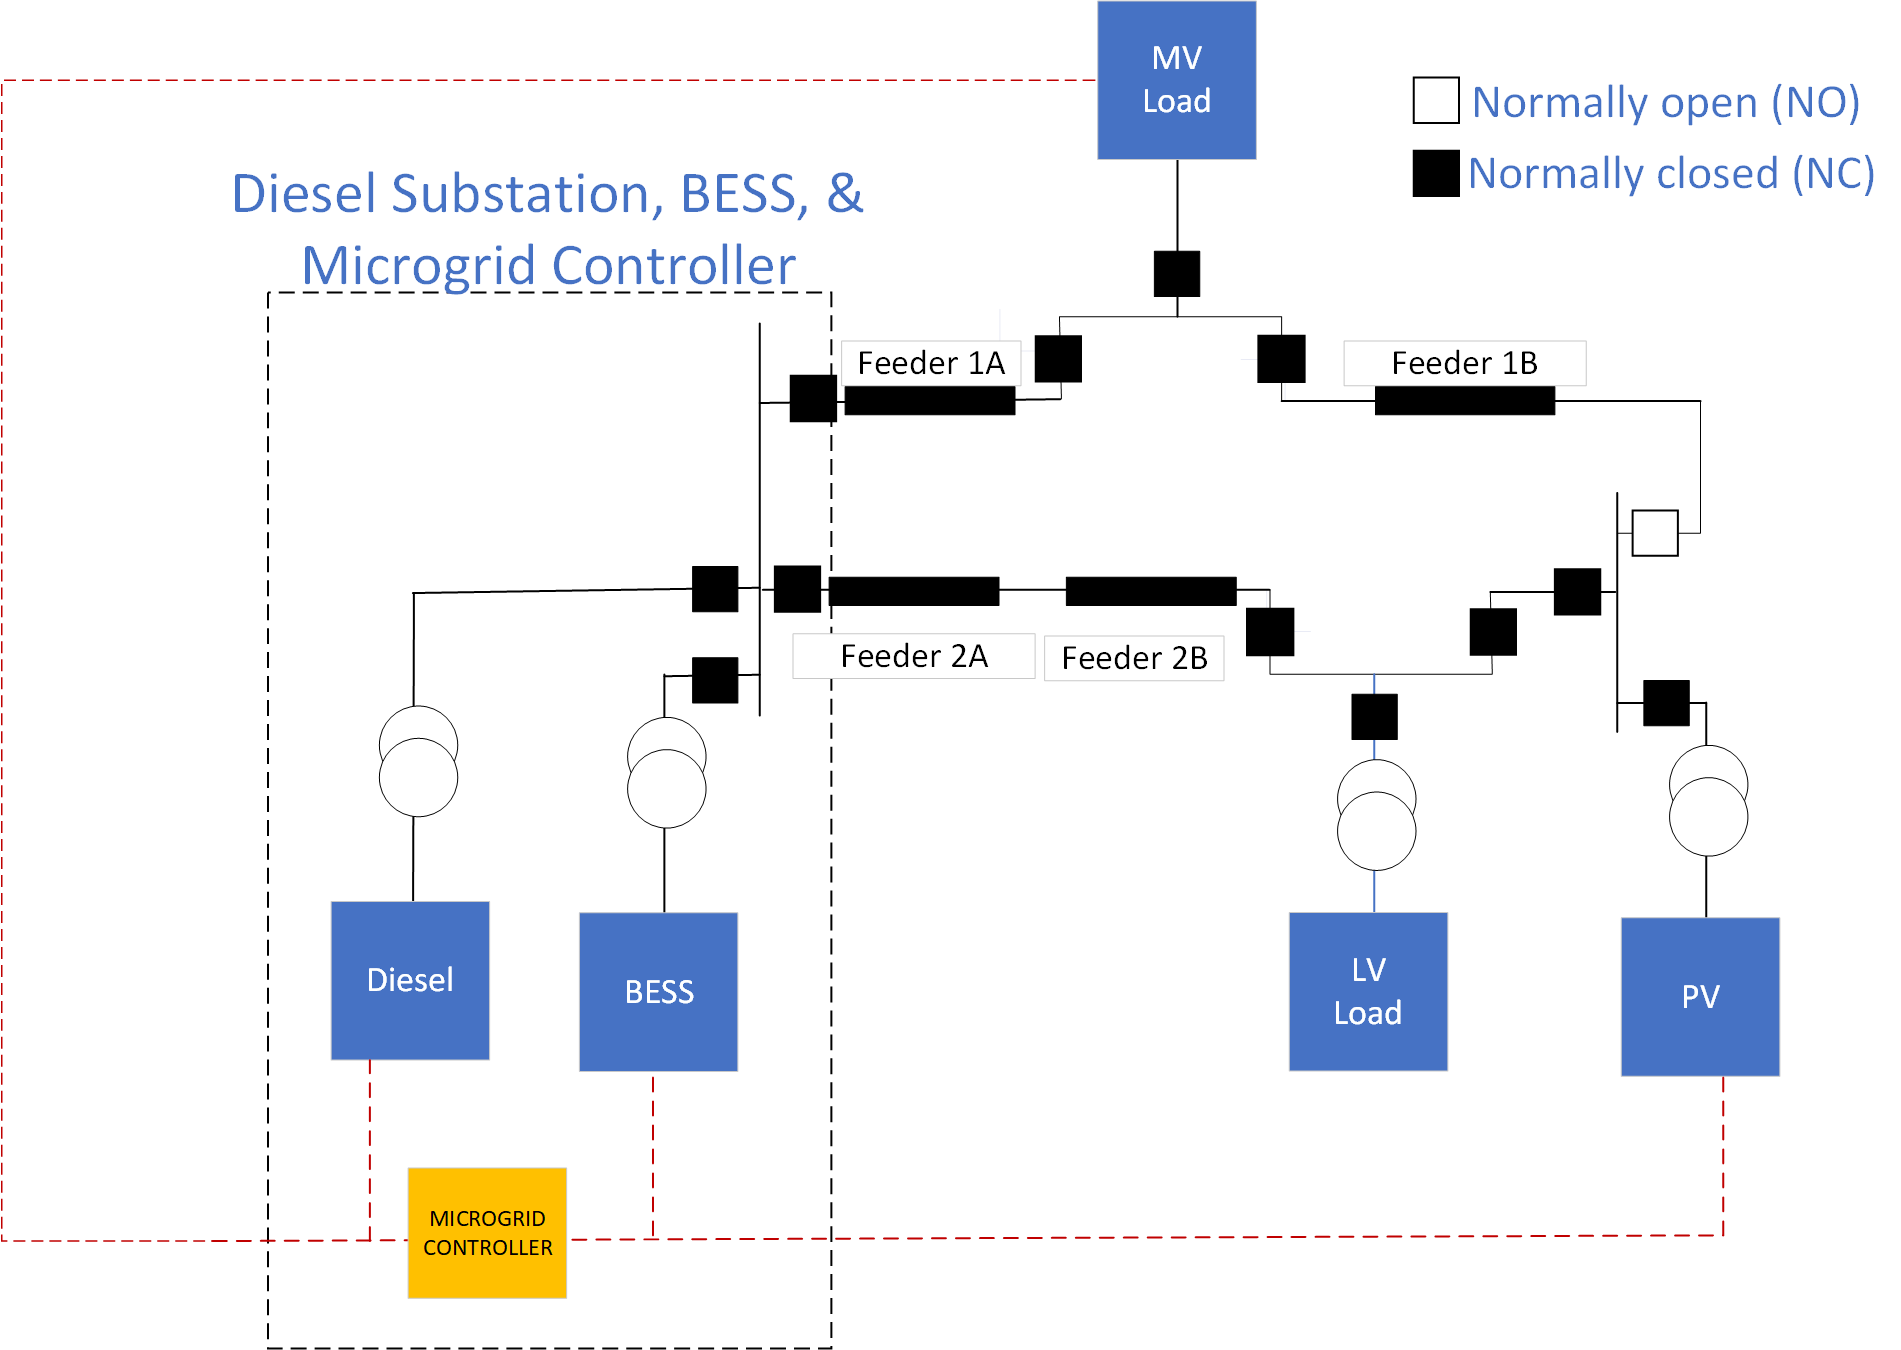

## Model for Remote Microgrid

### Model Overview

Open the model `remote_microgrid.slx`.

modelName = "RemoteMicrogrid";
open_system(modelName);

The Diesel Substation, BESS, & Microgrid Controller subsystem connects the diesel generator model to the microgrid model at the PCC. It hosts the model of diesel generator and the BESS connected at PCC. The diesel and BESS model connection are implemented with associated transformers and breakers. The microgrid controller model is also implemented at the substation.

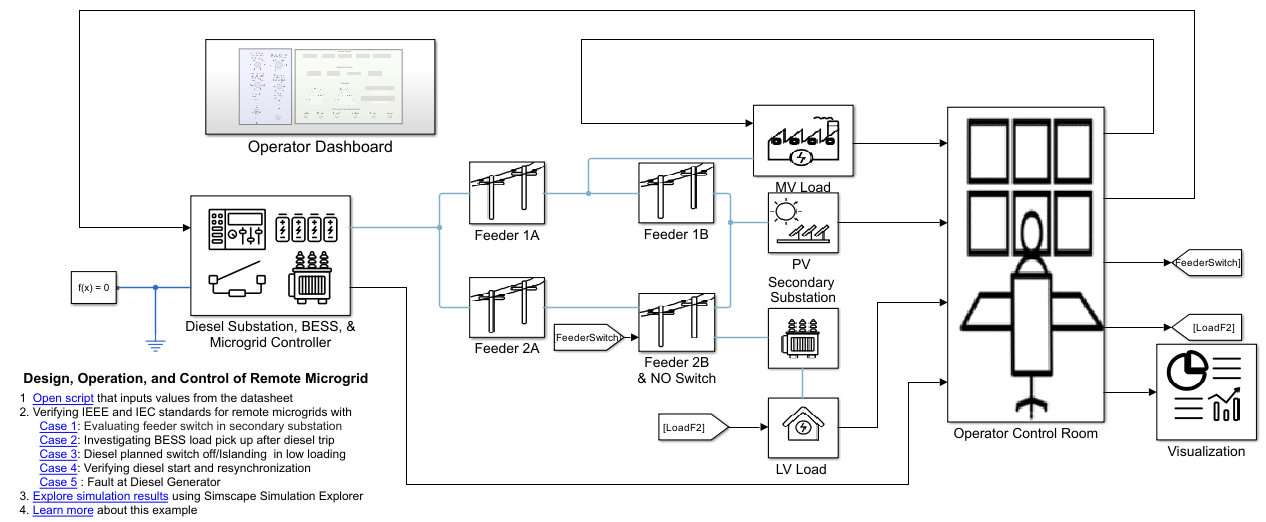

### Components for Remote Microgrid

This workflow comprises these main components:

- The BESS system represents the storage of the remote microgrid.

- The Diesel Substation, BESS, and Microgrid Controller subsystem connects the diesel generator to the microgrid.

- The Operator Control Room subsystem collects all setpoints and measurements.

#### Storage

The BESS system comprises: 

- Battery modules

- Grid-side converter, filter, measurement, and control

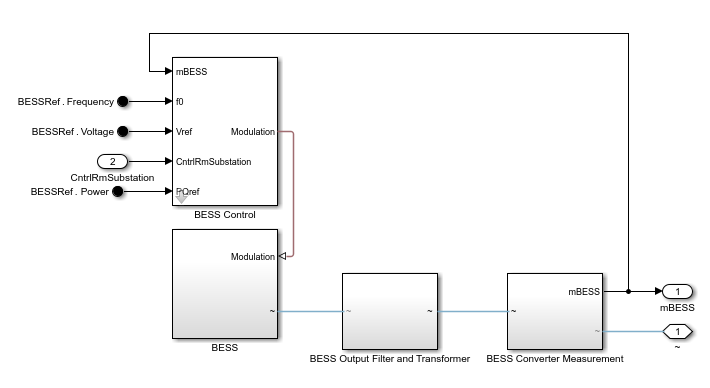

The BESS subsystem implements the BESS module and the BESS converter. The converter connects the battery modules to the grid and controls the power flow through the converter. The BESS Control subsystem regulates the voltage and the frequency based on the voltage and frequency references it receives from the microgrid controller. The BESS filter and transformer are modeled within the BESS Output Filter and Transformer subsystem. The BESS Converter Measurement subsystem measures the BESS output power, voltage, and current. This figure shows the control implementation.

 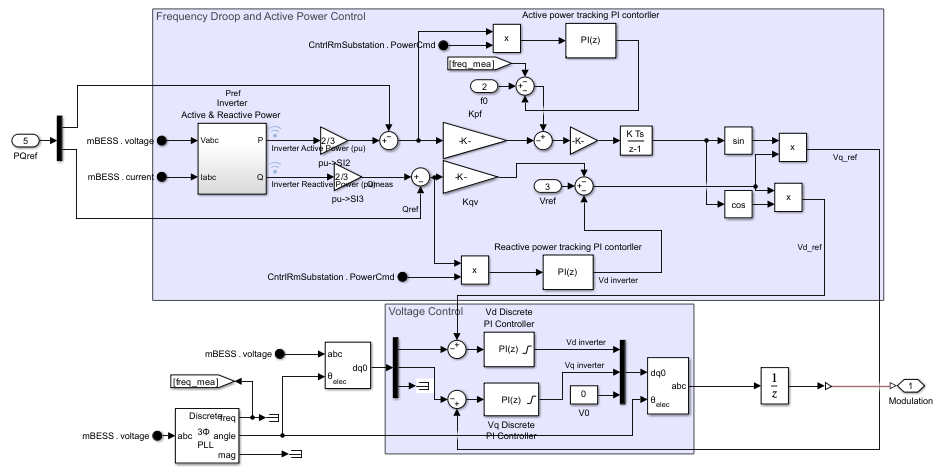

#### Diesel Substation, BESS, & Microgrid Controller

The Diesel Substation, BESS, & Microgrid Controller subsystem connects the diesel generator to the microgrid through the transformer and disconnectors. The measurements at PCC are modeled within PCC Measurement and PCC Breaker subsystem. The BESS and Controller subsystem with all the BESS components discussed before is connected at PCC. 

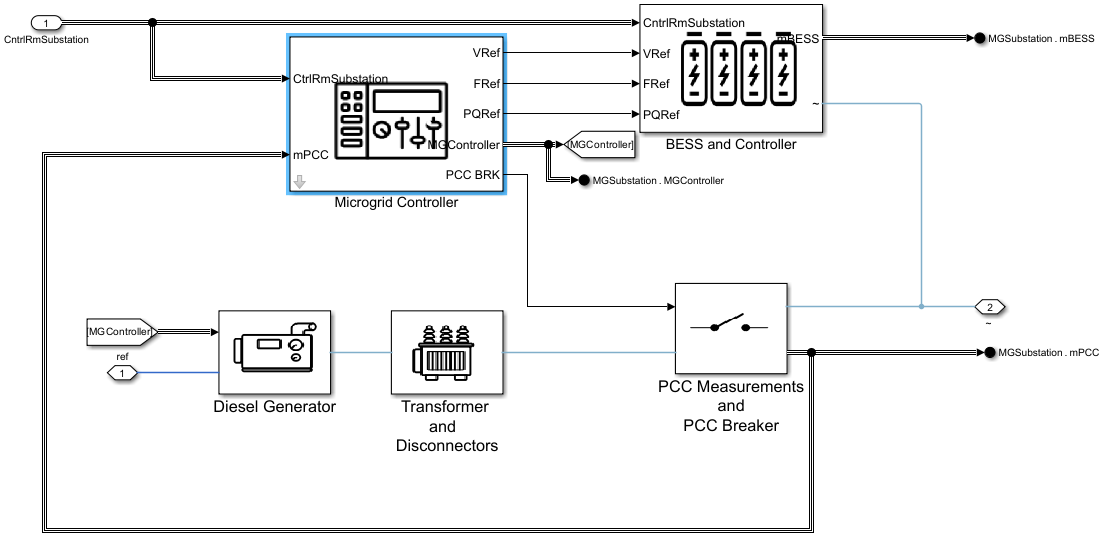

#### Microgrid Controller

The Microgrid Controller subsystem comprises :

- PLL

- Microgrid supervisory control

- Breaker Control

- Reference Generation

- Microgrid control functions

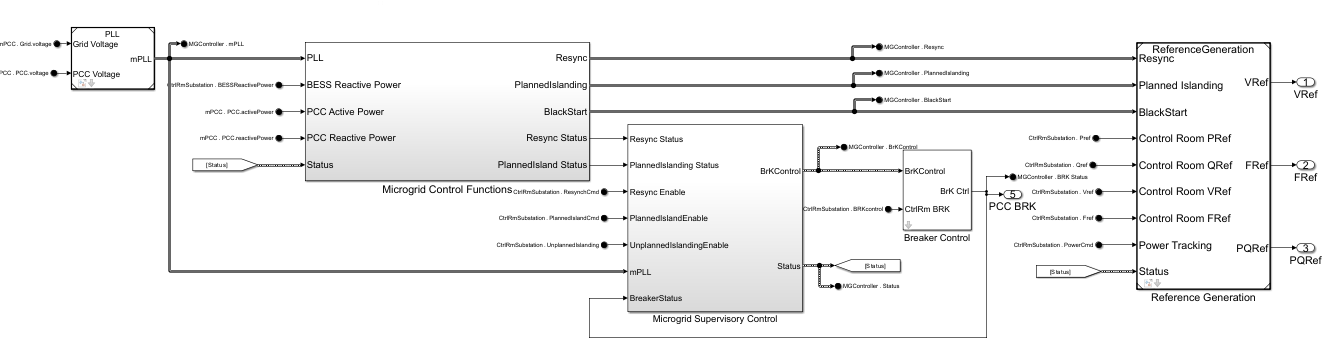

The Microgrid supervisory control implements the transition and dispatch functions by using Stateflow™. The transition functions include planned islanding, unplanned islanding, resynchronization, and black start. This example implements and shows the planned islanding, unplanned islanding, and resynchronization functions. The [IndustrialMicrogrid](http://./IndustrialMicrogridDesign.mlx) example implements and shows the black start function. The atomic charts of the transition functions implement the individual dispatch functions.

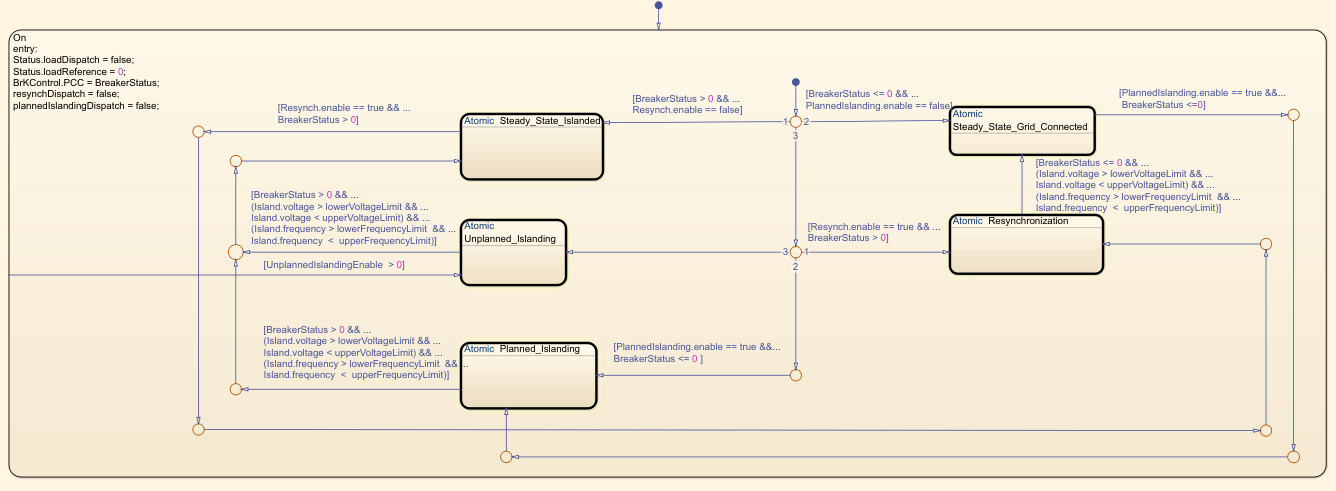

The Reference generation subsystem generates voltage, frequency, active power and reactive power references to the BESS. The Microgrid control functions comprise the planned islanding, resynchronization and black start models. Each of these transition functions are implemented as model reference. 

#### Operator Control Room

The Operator Control Room subsystem collects all the setpoints and commands. It also gathers the measured quantities and the system performance analysis.

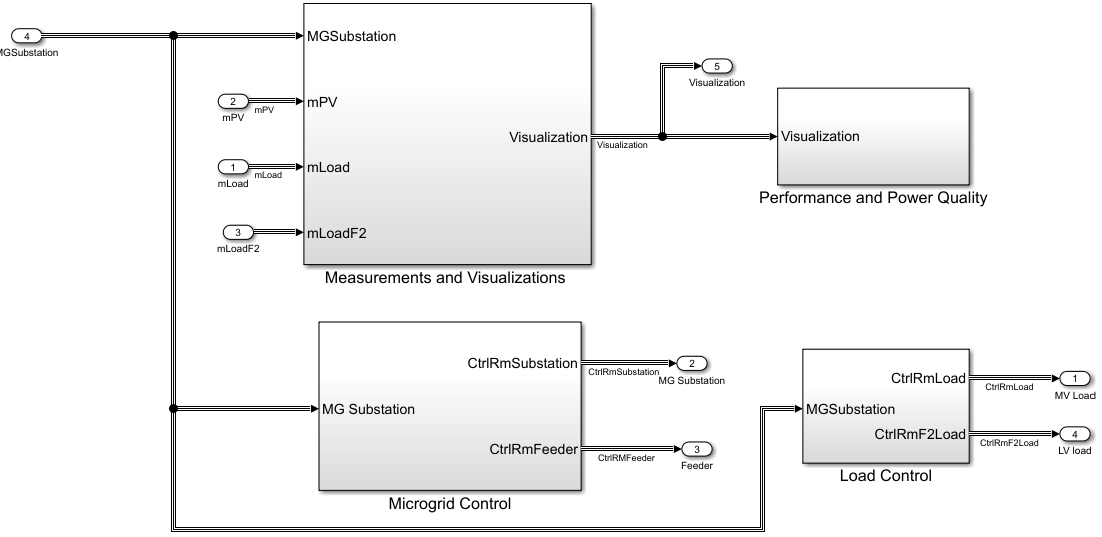

#### Operator Dashboard

The Operator Dashboard subsystem provides comprehensive control and monitoring within a microgrid environment. You can set the voltage, power, and frequency references for the BESS. Moreover, the dashboard provides real-time displays of voltage and power metrics at various points throughout the microgrid, offering a clear view of the energy distribution and consumption landscape. Additionally, the dashboard serves a crucial role in indicating the microgrid operating state, which is essential for maintaining system stability and operational integrity.

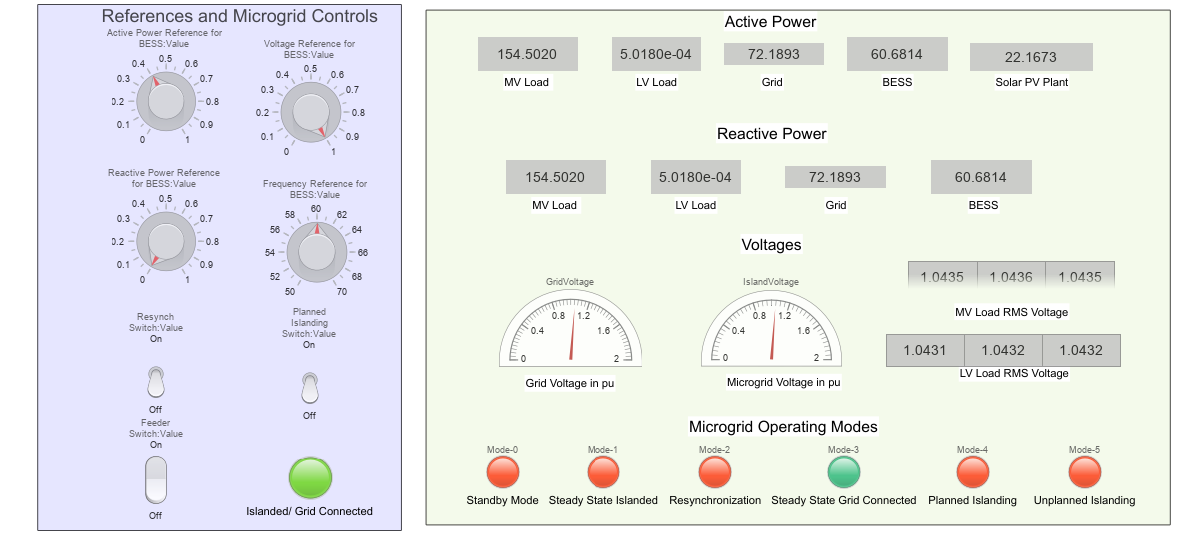

## Define Parameters and Run Simulations

To verify different microgrid operations, controller functions, and monitor system behaviours, you simulate different scenarios and compare the system performance to the existing standards. You can simulate four different scenarios in this study:

- Case 1: Evaluating feeder switch in secondary substation

- Case 2: Investigating BESS load pick up after diesel trip

- Case 3: Diesel planned switch off/islanding in low loading 

- Case 4: Verifying diesel start and resynchronization

- Case 5: Fault at Diesel generator

To initialize the BESS, diesel, and PV parameters for each case, at the MATLAB Command Window, run these commands according to the scenario you want to simulate.

For Case1:

For Case2:

For Case3:

For Case5:

## **Run Simulation **

These plots show the simulation results for each of the simulation scenarios:

- Voltage and current of BESS.

- Active and reactive power output of BESS, PV, load, and diesel.

- Voltage, current, and power consumption of MV and LV loads.

- RMS voltage and RMS current of the loads.

- Voltage, frequency, and phase matching for planned switch off and resynchronization of diesel cases (only for Case 3 and Case 4).

### Simulation of Case 1 — Evaluating Feeder Switch in Secondary Substation

Initialize the parameters for case 1 and run the model.

 
clear;
caseNum = 1;  
RemoteMicrogridInputData;
simoutData = sim('RemoteMicrogrid','SrcWorkspace','current');

### Starting serial model reference simulation build.
### Model reference simulation target for BlackStart is up to date.
### Model reference simulation target for PLL is up to date.
### Model reference simulation target for PlannedIsland is up to date.
### Model reference simulation target for ReferenceGeneration is up to date.
### Model reference simulation target for Resynchronization is up to date.

Build Summary

0 of 5 models built (5 models already up to date)
Build duration: 0h 0m 15.831s


voltageLimit = 0.1;
frequencyLimit = 0.02;
tStart = 5.9;
tStop = 6.1;
tEvent = 3;
powerPlotStart = 2.5;
powerPlotStop =8;

This plot shows the three-phase voltage and current output of the BESS and the diesel current. At 3 s, the feeder disconnects the upper feeder and connects the lower feeder to the LV load. At 6s, part of the LV load disconnects.

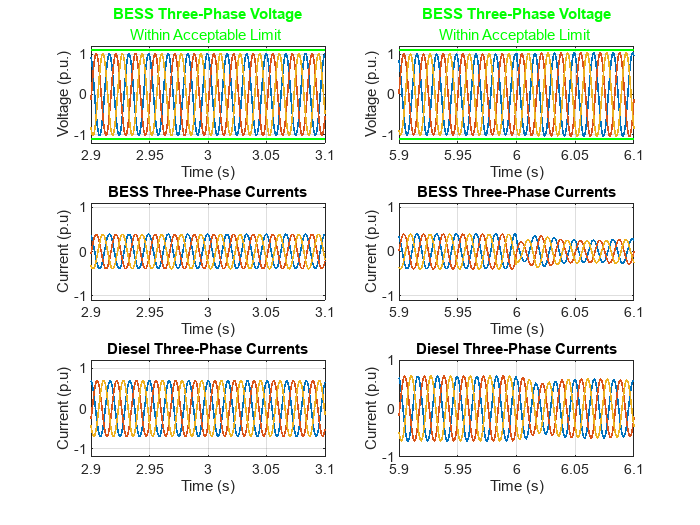

remoteMicrogridPlotBESSVI(simoutData.logsout_RemoteMicrogrid,voltageLimit,tEvent,tStart,tStop);

The stable voltage output and current output from BESS verify a stable control during the process.

This plot shows the active and reactive power of BESS, diesel, PV, and loads.

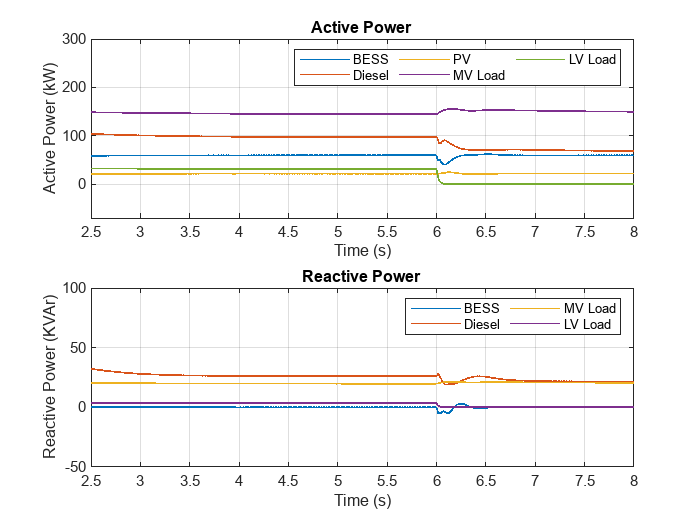

remoteMicrogridPlotPQ(simoutData.logsout_RemoteMicrogrid,powerPlotStart,powerPlotStop);

The stable active power output and reactive power output verify the efficacy of the control methods and microgrid operation.

This plot shows the voltage and current at the loads.

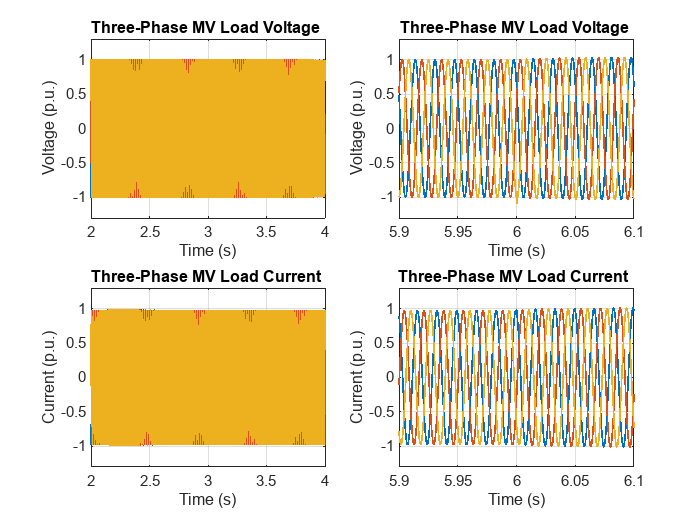

remoteMicrogridPlotLoadVI(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

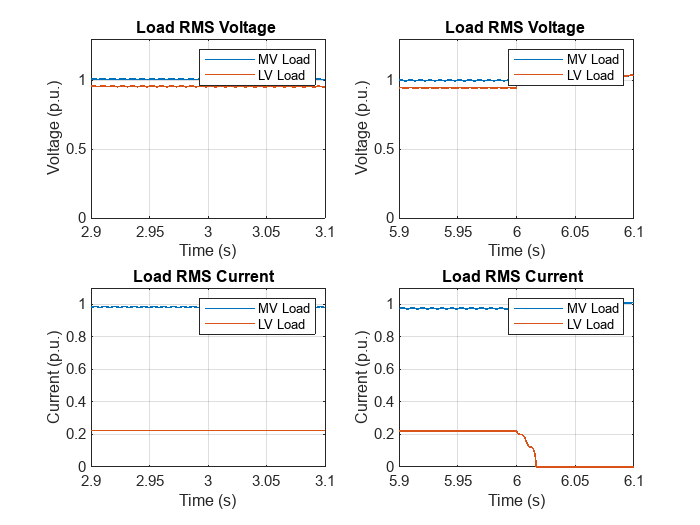

remoteMicrogridPlotLoadVIRMS(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

The load voltage and load current remain steady during feeder switch and LV load disconnection.

logsout1=simoutData.logsout_RemoteMicrogrid;
save('powerLoss1_RemoteMicrogrid','logsout1');

### Simulation of Case 2 — Investigating BESS Load Pick Up After Diesel Trip 

Initialize the parameters for case 2 and run the model.

 
clear;
caseNum = 2;  
RemoteMicrogridInputData;
simoutData=sim('RemoteMicrogrid','SrcWorkspace','current');

### Starting serial model reference simulation build.
### Model reference simulation target for BlackStart is up to date.
### Model reference simulation target for PLL is up to date.
### Model reference simulation target for PlannedIsland is up to date.
### Model reference simulation target for ReferenceGeneration is up to date.
### Model reference simulation target for Resynchronization is up to date.

Build Summary

0 of 5 models built (5 models already up to date)
Build duration: 0h 0m 13.09s


voltageLimit = 0.1;
frequencyLimit = 0.02;
tStart = 5.9;
tStop = 6.1;
tEvent = 3;
powerPlotStart = 2.5;
powerPlotStop =8;

At 3 s the diesel disconnects and the BESS picks up the extra power requirement. At 6 s one part of the LV load dsconnects. This plot shows the three-phase voltage and current output of the BESS, and the diesel current during diesel trip and LV load disconnection. 

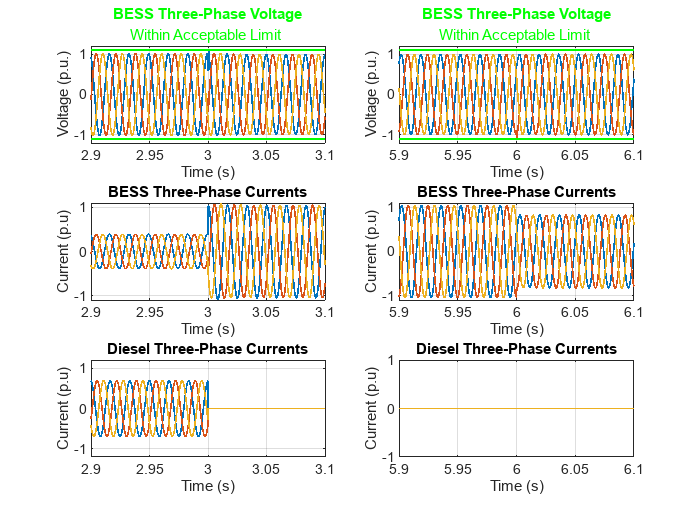

remoteMicrogridPlotBESSVI(simoutData.logsout_RemoteMicrogrid,voltageLimit,tEvent,tStart,tStop);

The stable voltage output and current output from BESS verify a good microgrid control during diesel trip. The BESS continues to form the grid and supports load change at 6s.

This plot shows the active and reactive power of BESS, PV, diesel, and loads.

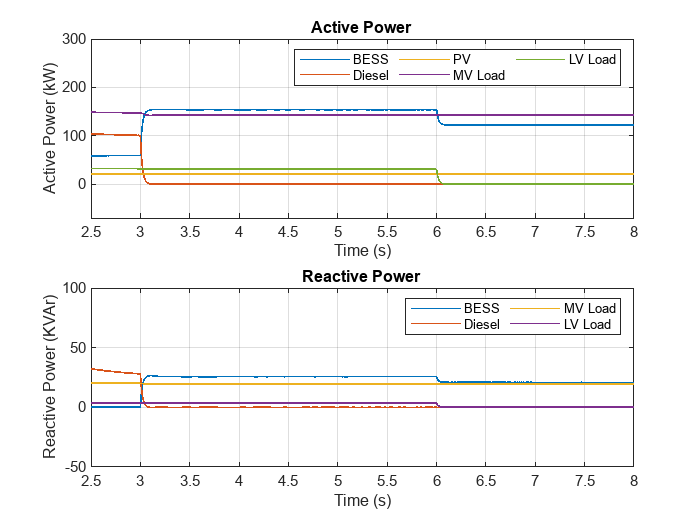

remoteMicrogridPlotPQ(simoutData.logsout_RemoteMicrogrid,powerPlotStart,powerPlotStop);

The stable active power output and reactive power output verify the efficacy of the operation. The diesel power output becomes zero after trip at 3s and the BESS picks up the extra power requirement.

This plot shows the voltage and current at the loads.

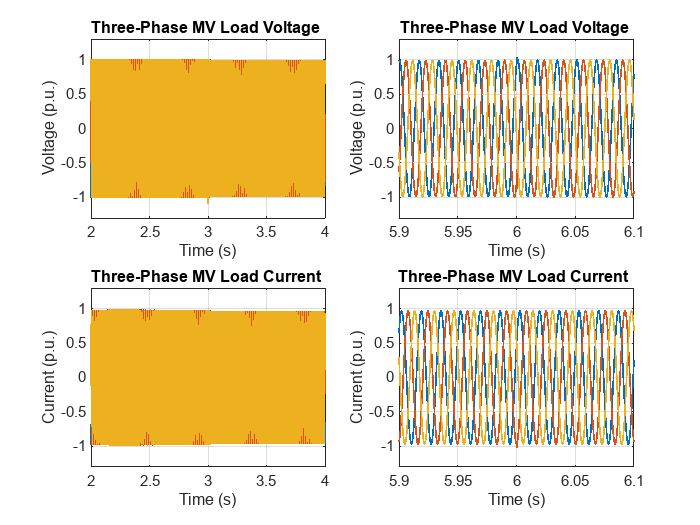

remoteMicrogridPlotLoadVI(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

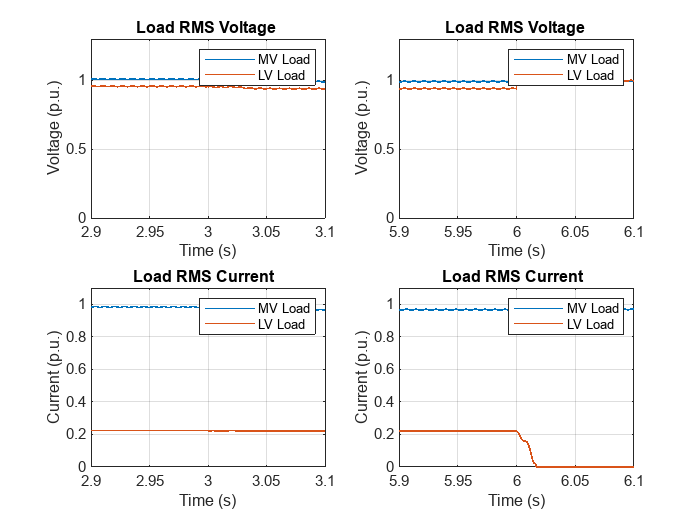

remoteMicrogridPlotLoadVIRMS(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

The load voltage and load current remain steady during diesel trip and LV load disconnection.

logsout2=simoutData.logsout_RemoteMicrogrid;
save('powerLoss2_RemoteMicrogrid','logsout2');

### Simulation of Case 3 — Diesel Planned Switch Off or Islanding in Low Loading

Initialize the parameters for case 3 and run the model.

 
clear;
caseNum = 3; %#ok<*NASGU> 
RemoteMicrogridInputData;
simoutData=sim('RemoteMicrogrid','SrcWorkspace','current');

### Starting serial model reference simulation build.
### Model reference simulation target for BlackStart is up to date.
### Model reference simulation target for PLL is up to date.
### Model reference simulation target for PlannedIsland is up to date.
### Model reference simulation target for ReferenceGeneration is up to date.
### Model reference simulation target for Resynchronization is up to date.

Build Summary

0 of 5 models built (5 models already up to date)
Build duration: 0h 0m 13.501s


voltageLimit = 0.1;
frequencyLimit = 0.02;
tStart = 7.2;
tStop = 7.4;
tEvent = 3;
powerPlotStart = 2.5;
powerPlotStop =8;

The efficiency of the diesel generator during low loading is poor and, if other sources of energy such as the BESS are available, it is preferable to switch it off. At 3 s the planned switch off of the diesel starts and around 7.3 s it reaches the zero power output from the diesel unit. This plot shows the three-phase voltage and current output of the BESS and the diesel current during the diesel planned switch off/islanding due to low loading. Stable voltage and current output of the BESS verify a smooth load pick up after diesel trip. 

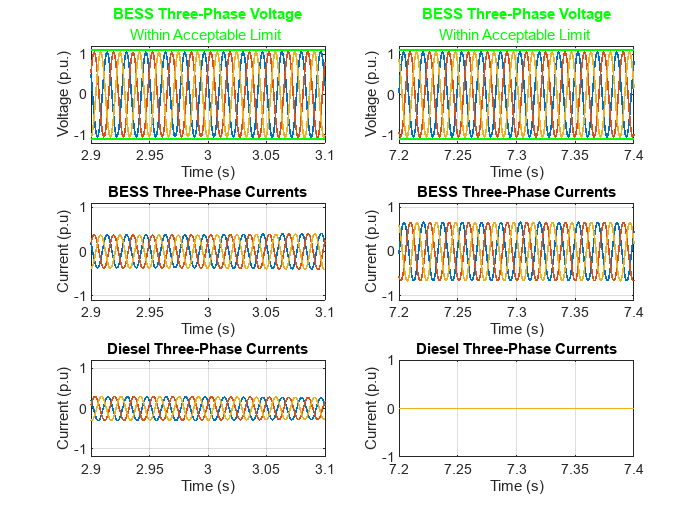

remoteMicrogridPlotBESSVI(simoutData.logsout_RemoteMicrogrid,voltageLimit,tEvent,tStart,tStop);

This plot shows the active and reactive power of BESS, PV, diesel, and loads.

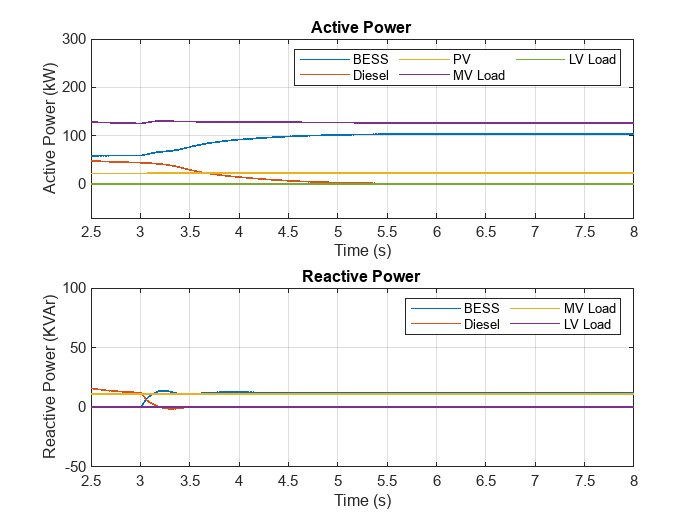

remoteMicrogridPlotPQ(simoutData.logsout_RemoteMicrogrid,powerPlotStart,powerPlotStop);

The stable active power output and reactive power output verify the efficacy of the control method.

This plot shows the voltage and current at the loads.

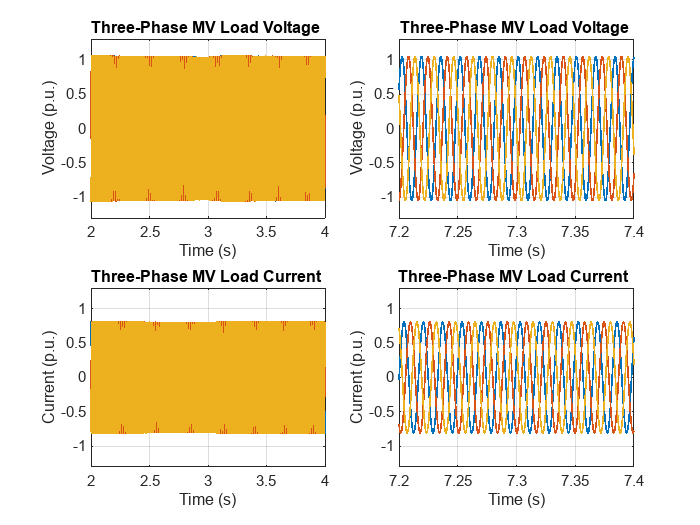

remoteMicrogridPlotLoadVI(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

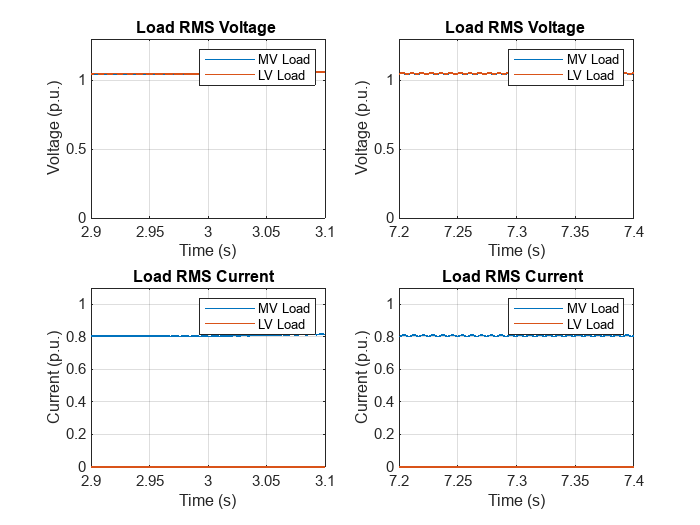

remoteMicrogridPlotLoadVIRMS(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

The load voltage and load current remain steady during the planned switch off of the diesel generator.

This plot shows the planned islanding command for diesel generator, islanding, and BRK (breaker) status. The Islanding and BRK Status signals are high when the power flow from the diesel is equal to zero. The voltage, frequency, and phase between microgrid and diesel generator are the same as they are connected together. The change in voltage, frequency, and phase shows necessary control actions to achieve zero power output from diesel. 

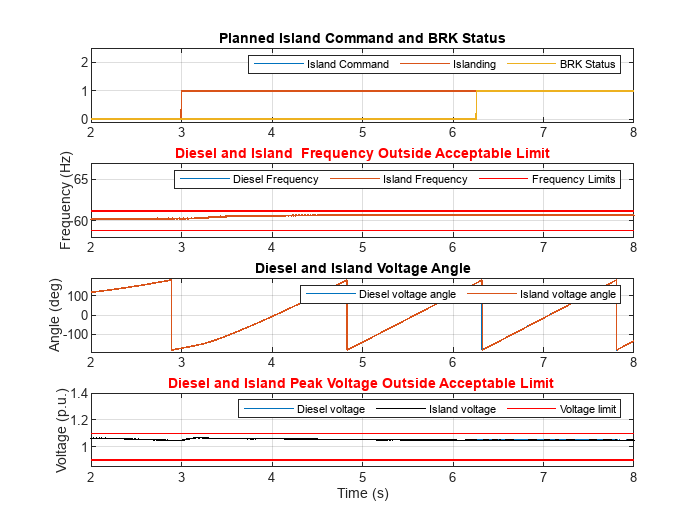

remoteMicrogridPlotFreAngle(simoutData.logsout_RemoteMicrogrid,caseNum,voltageLimit,frequencyLimit);

logsout3=simoutData.logsout_RemoteMicrogrid;
save('powerLoss3_RemoteMicrogrid','logsout3');

### Simulation of Case 4 — Verifying Diesel Start and Resynchronization

Initialize the parameters for case 4 and run the model.

 
clear;
caseNum = 4;
RemoteMicrogridInputData;
simoutData=sim('RemoteMicrogrid','SrcWorkspace','current');

### Starting serial model reference simulation build.
### Model reference simulation target for BlackStart is up to date.
### Model reference simulation target for PLL is up to date.
### Model reference simulation target for PlannedIsland is up to date.
### Model reference simulation target for ReferenceGeneration is up to date.
### Model reference simulation target for Resynchronization is up to date.

Build Summary

0 of 5 models built (5 models already up to date)
Build duration: 0h 0m 14.416s


voltageLimit = 0.1;
frequencyLimit = 0.02;
tStart = 7.4;
tStop = 7.6;
tEvent = 3;
powerPlotStart = 2.5;
powerPlotStop =8;

This plot shows the three-phase voltage and current output of the BESS and the grid current during the diesel start and the resynchronization to the diesel generator.

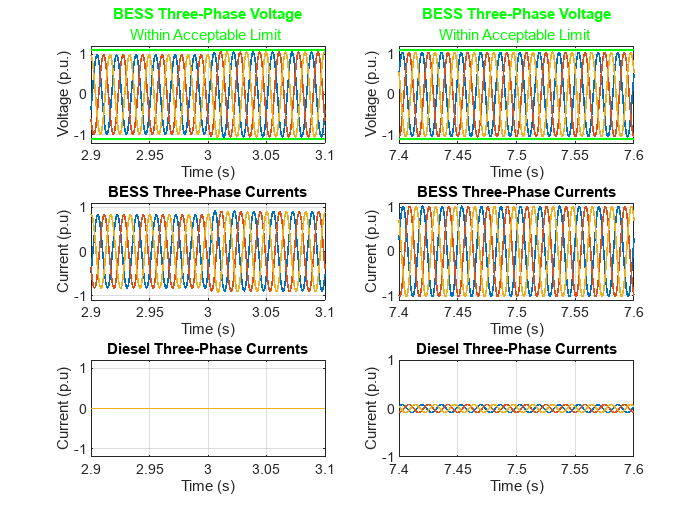

remoteMicrogridPlotBESSVI(simoutData.logsout_RemoteMicrogrid,voltageLimit,tEvent,tStart,tStop);

The plot shows the measured values around the resynchronization command at 3.0 s and the actual resynchronization around 7.7 s. The stable voltage output and current output from BESS verify a good control. 

This plot shows the active and reactive power of BESS, PV, diesel, and loads.

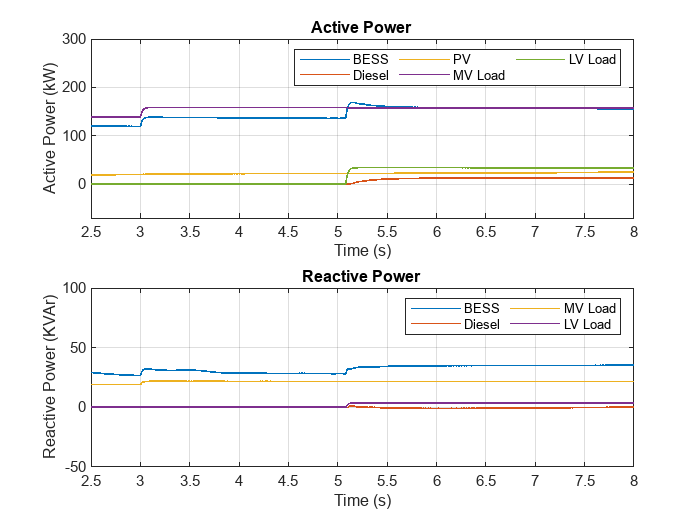

remoteMicrogridPlotPQ(simoutData.logsout_RemoteMicrogrid,powerPlotStart,powerPlotStop);

The stable active power output and reactive power output verify the efficacy of the resynchronization to diesel generator.

This plot shows the voltage and current at the loads.

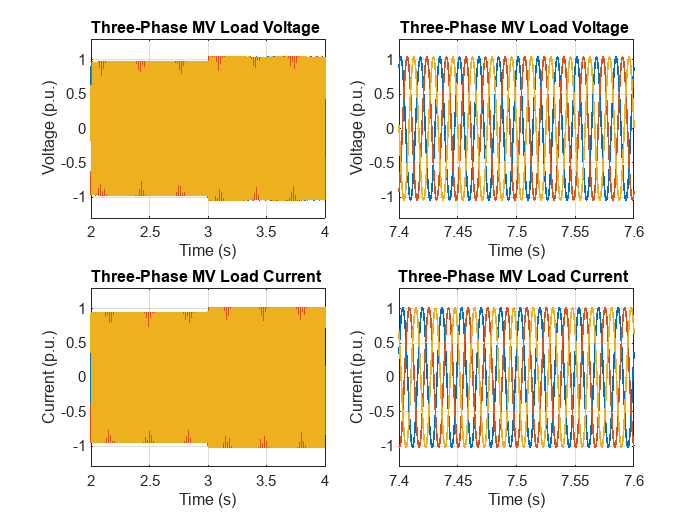

 remoteMicrogridPlotLoadVI(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

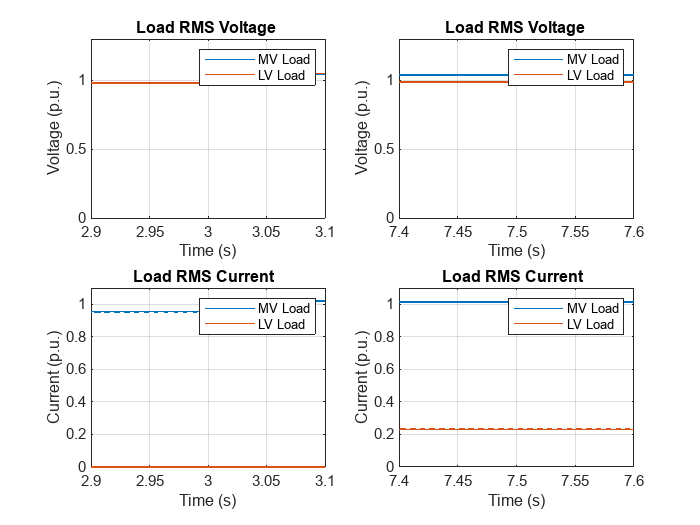

 remoteMicrogridPlotLoadVIRMS(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

The load voltage and load current remain steady during the resynchronization process.

This plot shows the resynchronization command and matching of voltage, frequency, and phase between the microgrid and the diesel generator. Although the steady state island voltage is within the acceptable limit, the overshoot during resynchronization command crosses the limit (fourth plot). You can design your microgrid response by tuning the microgrid resynchronization controller to avoid large overshoots. 

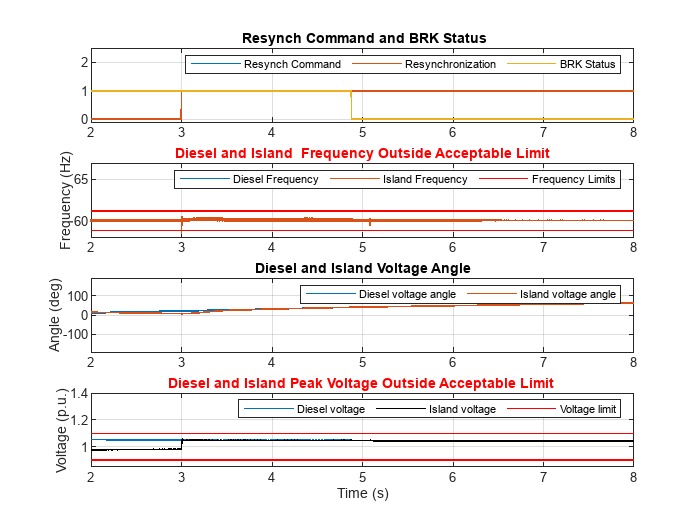

remoteMicrogridPlotFreAngle(simoutData.logsout_RemoteMicrogrid,caseNum,voltageLimit,frequencyLimit);

logsout4=simoutData.logsout_RemoteMicrogrid;
save('powerLoss4_RemoteMicrogrid','logsout4');

### Simulation of Case 5 — Fault at Diesel generator

Initialize the parameters for case 5 and run the model. To demonstrate the unplanned islanding scenario,this example creates a fault near the diesel generator. An overcurrent relay gives the trip signal to the PCC circuit breaker in the event of high currents. The overcurrent relay resides in the RemoteMicrogrid/Operator Control Room/Microgrid Control/Protection & Power Tracking subsystem. You can configure the overcurrent relay according to the requirements. In this example, relay characteristics are set to definite time with a pick up current of 1.1A for 0.5 sec.

 
clear;
caseNum = 5;
RemoteMicrogridInputData;
simoutData=sim('RemoteMicrogrid','SrcWorkspace','current');

### Starting serial model reference simulation build.
### Model reference simulation target for BlackStart is up to date.
### Model reference simulation target for PLL is up to date.
### Model reference simulation target for PlannedIsland is up to date.
### Model reference simulation target for ReferenceGeneration is up to date.
### Model reference simulation target for Resynchronization is up to date.

Build Summary

0 of 5 models built (5 models already up to date)
Build duration: 0h 0m 15.319s


voltageLimit = 0.1;
frequencyLimit = 0.02;
tStart = 5.9;
tStop = 6.1;
tEvent = 3;
powerPlotStart = 2.5;
powerPlotStop =8;

This plot shows the three-phase voltage and current output of the BESS and the grid current during the diesel start and the resynchronization to the diesel generator.

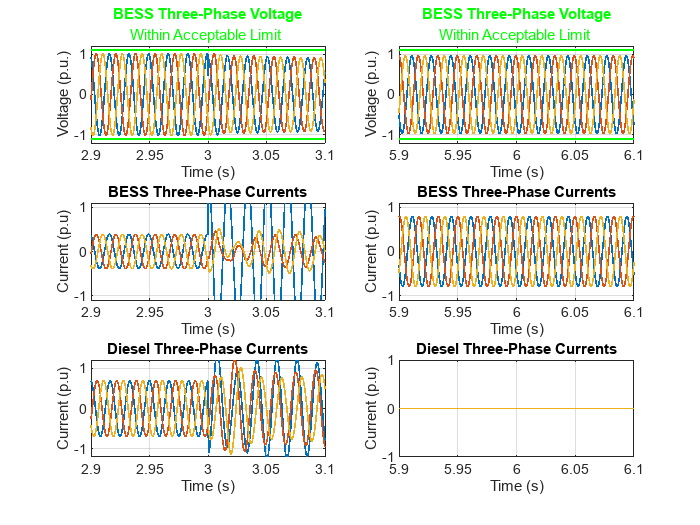

remoteMicrogridPlotBESSVI(simoutData.logsout_RemoteMicrogrid,voltageLimit,tEvent,tStart,tStop);

The plot shows the measured values around the fault at 3.0 s . The stable voltage output and current output from BESS after the unplanned islanding verify a good control. 

This plot shows the active and reactive power of BESS, PV, diesel, and loads.

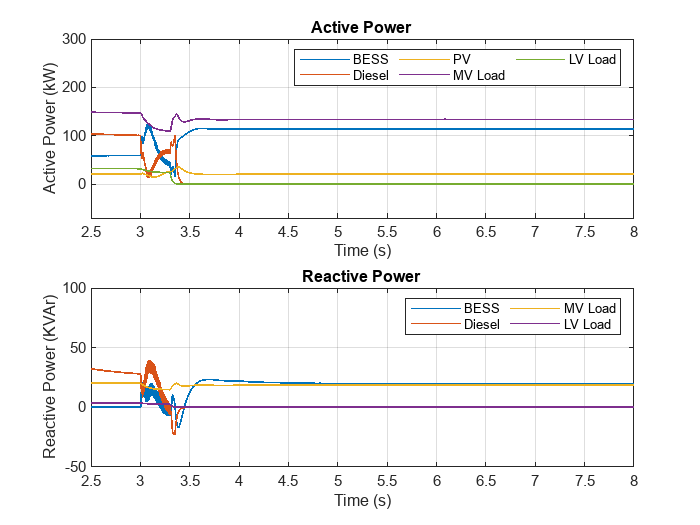

remoteMicrogridPlotPQ(simoutData.logsout_RemoteMicrogrid,powerPlotStart,powerPlotStop);

The stable active power output and reactive power after the unplanned islanding output verify the efficacy of the microgrid control during unplanned islanding.

This plot shows the voltage and current at the loads.

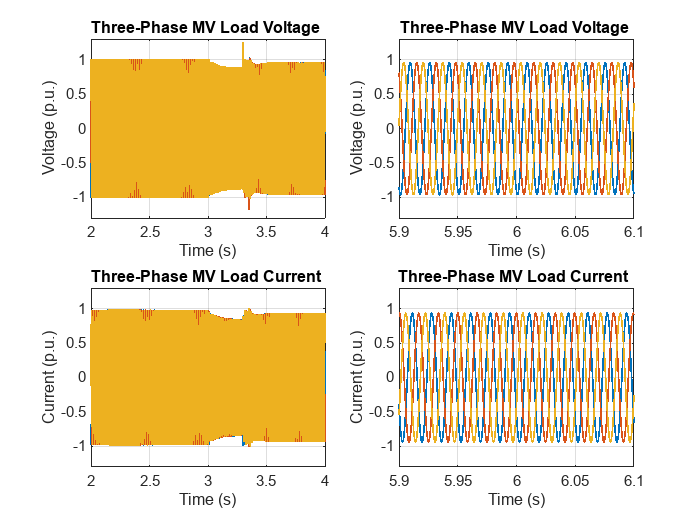

remoteMicrogridPlotLoadVI(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

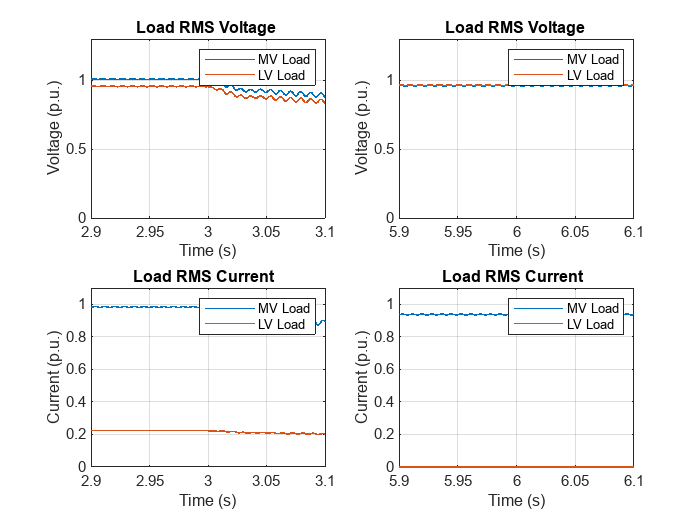

remoteMicrogridPlotLoadVIRMS(simoutData.logsout_RemoteMicrogrid,tEvent,tStart,tStop);

The load voltage and load current remain steady during the islanding process.

## Evaluate System Performance

The plots in this section show the results of the system performance, system design, and reduction in diesel usage .

 These performance indices include:

- Maximum and minimum deviation in voltage and frequency for four cases.

- Transient overshoot and steady state deviation in voltage and frequency for a single-feeder and double-feeder system for the microgrid in this study.

- Reduction in diesel usage with larger size of BESS. 

This plot shows the voltage and frequency deviations in each of the four cases. The voltage and frequency remain within acceptable ranges for all the cases. This validates the efficacy of the microgrid control of this study.

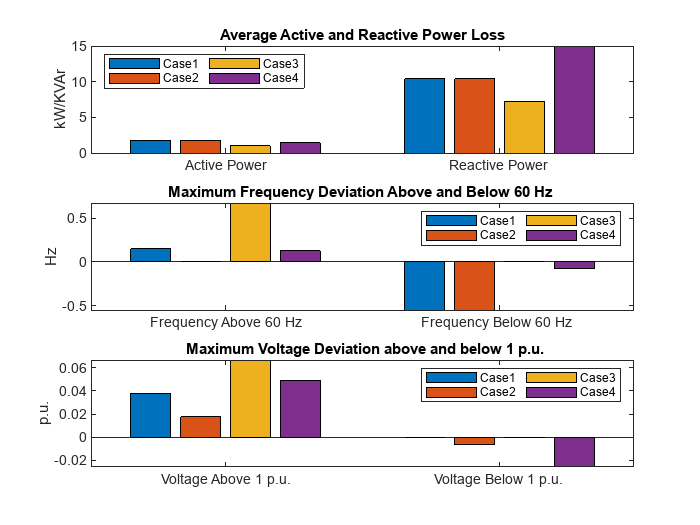

RemoteMicrogridLoss;

 This plot shows the total harmonic distortion (THD) of the load voltage and PCC voltage. It also shows the maximum and minimum load voltage. Monitoring the THD of the load voltage and PCC voltage helps to ensure power quality in the microgrid operations. You can define the acceptable THD and load voltage in the [RemoteMicrogridInputData](matlab:open('./RemoteMicrogridInputData.mlx')). In this study the THD and load voltage deviation limits are set to 3% and 0.1 p.u. respectively. The plot shows the THD and the load voltage variations are within the set limit for all the cases.

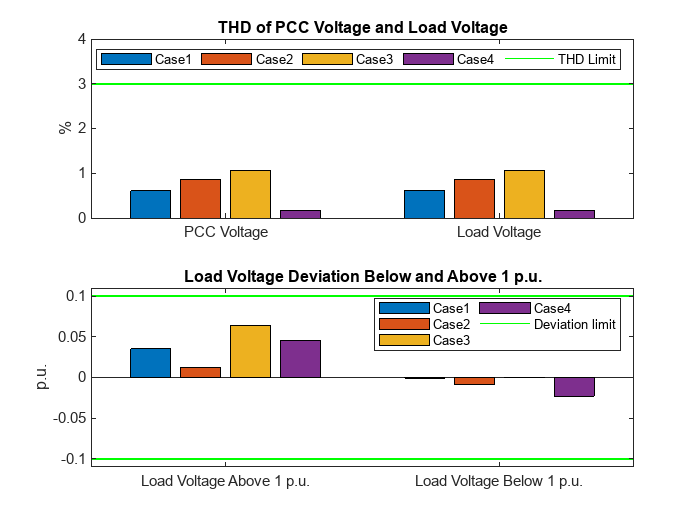

RemoteMicrogridTHDLoad;

To explain how the selection of the BESS size changes the cost of the diesel, these two plots show an assumed diesel generator loading for 24 hours and cost of diesel with various diesel-to-BESS rating ratio. The first plot shows the assumed diesel loading during the day. The second plot shows the required diesel rating, diesel consumptions, and diesel cost, with the variation in BESS size in five scenarios(from 250 KVA to 50 KVA). A larger BESS increases the cost of BESS but a smaller BESS results in a higher cost of diesel. The optimized ratio of BESS and diesel must be selected based on BESS cost and diesel cost at the project location. You can select the cost data in the [RemoteMicrogridInputData](matlab:open('./RemoteMicrogridInputData.mlx')). For the assumed values in this study, the diesel cost dominates the combined cost and it is economical to select a larger BESS to reduce the diesel cost.

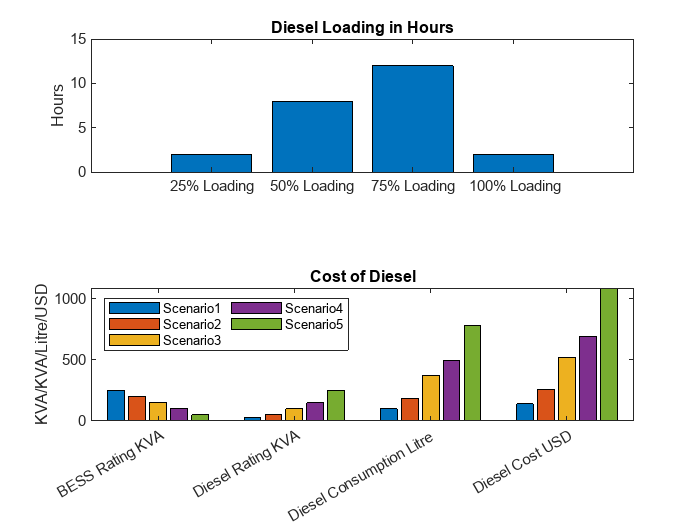

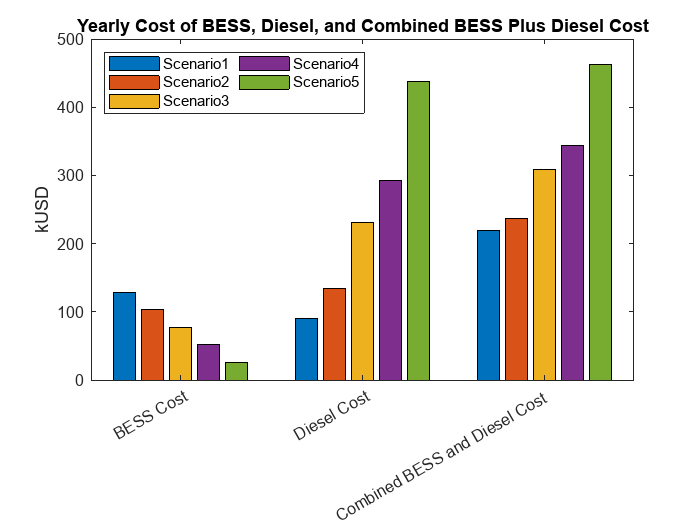

RemoteMicrogridDieselCost;

Copyright 2022 - 2024 The MathWorks, Inc.